# Robbins_Copyright2025_AQAM_Ch12_Regime_Identification_in_VECM_Frameworks

Copyright © 2025 Michael Robbins. Licensed under the Apache License 2.0 (the "License"); you may not use this file except in compliance with the License. Obtain a copy at http://www.apache.org/licenses/LICENSE-2.0. Distributed on an "AS IS" BASIS, WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied. See the License for specific terms and limitations.

Problem Statement (Context and Motivation)

- Adaptive Regime Detection in Rolling-Window VECM Modeling for Tading Strategy Indentification

- Adaptive Regime Detection in Rolling-Window VECM Modeling for Missing Data Imputation and Outlier Detection and Replacement

Discussion

- Limitations of As-Is Solutions

- Core Challenges

- Methodological Requirements  

- Theoretical Foundations of Regime-Dependent VECMs

- Theoretical Foundations of Regime Identification in Cointegrated Systems

- Bartlett Correction for Johansen Cointegration Tests

- Correcting VECM Coefficient Covariance Estimates Using HAC Methods

- Regime Identification

- Threshold VECM with Automated Parameter Optimization

Code

- Data Preparation

- Parameter Optimization Framework

- Grid Search Execution

- Regime Identification

- Model Selection

- Diagnostic Plots

-     Grid Search Results

-     Time Series Regimes

-     Parameter stability plot

-     Regime Transition 

- Optimal Parameter Selection

# PROBLEM STATEMENT

# Adaptive Regime Detection in Rolling-Window VECM Modeling for Tading Strategy Indentification

## Context and Motivation

A VECM with threshold regimes can be used for trading by identifying deviations from long-run equilibrium relationships among cointegrated assets and classifying market conditions into regimes based on the Error Correction Term (ECT). Thresholds define neutral regimes, where prices are near equilibrium, and outer regimes, where significant deviations signal overbought or oversold conditions. Trading strategies leverage mean-reversion dynamics, buying undervalued assets in negative outer regimes and selling overvalued assets in positive outer regimes.

Momentum can be incorporated by adjusting position sizes based on the magnitude of ECT deviations, capturing the persistence of trends before reversion occurs.

Volatility, measured as the trace of the covariance matrix of innovations, can further refine regime classification by distinguishing high-risk trading periods from stable ones, ensuring trades are executed in favorable market conditions. This approach systematically exploits mispricing opportunities while managing risk through momentum and volatility-based adjustments.

# Adaptive Regime Detection in Rolling-Window VECM Modeling for Missing Data Imputation and Outlier Detection and Replacement

## Context and Motivation

We discussed how traditional data engineering techniques are insufficient for financial time series in Chapter 5 of Quantitative Asset Management[12]. Specifically, when imputing missing data and replacing outliers, methods like forward-fill and interpolation are incorrect at best.

Financial data has many univariate and conincident features not present in traditional time series that we can use to enhance our analysis. The techniques in this section exploit univariate features like trend and seasonality, along with information from cointegrated time series to identify bad values and to replace them.

In an attempt to impute missing data and outliers, we explore several more sophisticated tecnhiques: **Vector Error Correction Models** (VECMs) and  **Multivariate Singular Spectrum Analysis** (MSSA)[13][14]. This example will discuss VECMs, which incorporate autoregression and cointegration, and the next will discuss MSSA.

There are challenges to using these methods. They were not designed for this purpose. One hurdle for traditional VECMs comes from the assumption of linear adjustment dynamics and static parameters, which often fail to capture the nonlinear behavior of financial time series characterized by regime shifts (e.g., market turbulence vs. stability). We seek to:

- *dynamically adjust VECM parameters* across volatility/arbitrage regimes[17],

- *quantify implicit values*, like transaction costs,[15] via threshold estimates[2], and

- *outperform linear VECMs* in forecasting persistent basis deviations (e.g., credit risk premia[2]).

# DISCUSSION

## Limitations of As-Is Solutions

Financial data is conditioned on it state (regime). For example, covariances increase during panics and decrease during controlled rallies. Naive **rolling window **methods might be an intuitive first choice but ignore these important nuances. Other, more appropriate, methods have been devised.

**Threshold VECMs **(TVECMs), **online VECMs**,[e] and **Markov-switching VECMs** (MS-VECMs) address this by introducing regime-dependent parameters, but existing implementations face three critical limitations:  

- *Parameter Rigidity*: Most VECM frameworks fix the cointegrating vector and thresholds *a priori*[3][5], ignoring time-varying economic relationships. This leads to suboptimal forecasts when structural breaks occur in the cointegrating space or adjustment dynamics.  

- *Training Window Uncertainty*: Rolling-window VECMs typically use arbitrary window sizes (e.g., 1 year) and re-estimation frequencies (e.g., monthly), with no systematic method to adapt these to changing volatility regimes or transaction costs[2].

- *Regime Identification Challenges*:  Existing threshold detection methods (e.g., Sup-LM tests[3][4]) require pre-specified cointegrating vectors, while clustering-based approaches lack formal statistical grounding for regime classification[1]. 

## Core Challenges

This exercise addresses the following open problems in regime-aware VECM modeling:  

- *Joint Optimization of Model Parameters*:  Simultaneously determine (a) optimal training window size, (b) re-estimation frequency or "step," (c) cointegration rank, and (d) lag structure while accounting for transaction costs and arbitrage boundaries inferred from threshold regimes[2].  

- *Regime-Dependent Estimation*: Develop a unified framework that: (a) detects thresholds in the error-correction term (ECT) without prior knowledge of the cointegrating vector[3]; (b) aAllows at least two regimes to capture asymmetric arbitrage costs (e.g., positive vs. negative basis trading[2]), and (c) integrates Markov-switching variance-covariance matrices[1]  

- *Statistical Validation*: Formalize: (a) a modified AIC/BIC criterion for regime comparisons that penalizes threshold parameter proliferation; (b)  bootstrap procedures for Sup-LM tests with estimated cointegrating vectors[4]; and (c) E*conomic value tests* comparing regime-adaptive vs. linear VECM forecasts  

## Methodological Requirements  

The solution must:

- *Generalize TVECM/MS-VECM:* Incorporate both threshold-driven (TVECM) and Markov-switching (MS-VECM) regime logic[1][2]  

- *Automate Parameter Search*: Use grid optimization with likelihood-ratio constraints to identify: $\{\hat{\theta}_L, \hat{\theta}_U\} = \arg \min_{\theta} \left[ \text{AIC}(H_3) - \text{AIC}(H_2) \right]$ where $H_2 ,  H_3$denote 2-/3-regime models[2]  

- *Ensure Computational Feasibility*: Implement dynamic programming for nested window-size optimization and GPU acceleration for regime classification (GMM clustering[1]).

## **Footnotes**

See Problem Statement Citations.

## Theoretical Foundations of Regime-Dependent VECMs

Regime-switching VECMs enhance parameter adaptability in nonstationary financial datasets by aligning model specifications with latent market states. TVECMs excel in environments with clear threshold-driven regimes (e.g., arbitrage boundaries), while MS-VECMs offer flexibility for probabilistic state transitions. Integrating these with dynamic window selection mitigates overfitting and improves forecast accuracy. Future work should explore hybrid models combining threshold and Markov-switching mechanisms for high-dimensional portfolios[22][28].

## 1. Threshold VECMs (TVECMs)

TVECMs partition data into discrete regimes based on the magnitude of deviations (explicit thresholds) from a long-run cointegrating equilibrium (error correction term, ECT). The model assumes distinct dynamics in each regime, such as asymmetric adjustment speeds during periods of high volatility or arbitrage activity.  TVECMs are limited to predefined threshold variables and may employ expensive grid-search methods to identify useful values. TVECMs identify no-arbitrage bands in futures-spot basis trades, with regimes triggered by transaction cost thresholds[4][17].  

Parameter Identification:  

- *Cointegrating Vector*: Estimated via Johansen's procedure (JIT) or Engle-Granger two-step method (EGCIT).  

- *Thresholds*: Determined through grid search or sup-Lagrange multiplier (SupLM) tests to maximize log-likelihood across candidate thresholds[4][17].  

- *Regime-Specific Dynamics*: Conditional least squares or maximum likelihood (ML) estimation within each regime[12][17].  

Benefits:  

- Captures nonlinear adjustments to equilibrium, such as arbitrage-triggered mean reversion in stock pairs[4][7].  

- Reduces forecast errors by isolating periods where linear VECMs fail[9][20].  

## 2. Markov-Switching VECMs (MS-VECMs)

MS-VECMs allow probabilistic transitions between regimes, governed by a hidden Markov chain. Regimes may differ in adjustment coefficients, volatility, or lag structures.  MS-VECMs can accommodates unobserved latent factors but the EM algorithms used scale poorly with dimensions[5][22] Regimes: MS-VECMs can isolate macroeconomic regimes, e.g., recessionary states, with slower adjustment speeds and higher volatility[14][21].  

Parameter Identification:  

- *Transition Probabilities*: Estimated via **Expectation-Maximization **(EM) algorithms, iterating between regime classification and parameter updates[5][21].  

- *Regime-Specific Coefficients*: Bayesian hierarchical priors or ML estimation with shrinkage to stabilize high-dimensional parameter spaces[5][22].  

Benefits:  

- *Accommodates gradual regime shifts* (e.g., bull-to-bear markets) without predefined thresholds[14][21].  

- *Improves robustness to structural breaks* in rolling-window analyses[28].  

## 3. Adaptive Rolling-Window VECMs

Fixed rolling windows often fail to adapt to changing volatility or cointegration stability. Adaptive approaches dynamically adjust window lengths to balance bias-variance trade-offs:  

- *Volatility-Regulated Windows:* Shorten windows during high volatility (detected via GARCH or regime filters) to prioritize recent data[2][15].  

- *Cointegration Stability Tests: *Extend windows when cointegrating relationships exhibit low residual variance[6][16].  

Implementation:  

- *Tests:* Use the SupLM test for threshold detection or Bai-Perron tests for structural breaks to trigger window resets[9][29].  

- *Optimize window length *via cross-validation targeting minimum MSFE (mean squared forecast error)[29]. For example, for a 3-regime TVECM, the optimal window L scales with $T^{4/5}$, where T is the sample size, to minimize forecast variance while capturing regime persistence[29]. 

## Footnotes

See Theoretical Foundations Citations

## Theoretical Foundations of Regime Identification in Cointegrated Systems

The identification of structural regimes in vector error correction models (VECMs) requires addressing critical challenges:

- *Detecting nonlinear thresholds* in the error-correction mechanism,

- *Selecting optimal lag structures within regimes, and*

- Controlling for overfitting.

Threshold VECMs (TVECMs) formalize this by partitioning the error-correction term (ECT) into discrete states where adjustment dynamics differ significantly[3][6][13]. Unlike heuristic clustering approaches (e.g., K-means) which lack a theoretical foundation for regime identification and fail to control for Type I/II errors when applied to VECM parameters[6][13], formal statistical tests such as Hansen and Seo's (2002) Sup-LM test provide a rigorous framework for threshold detection while accounting for the unknown cointegrating vector[3][6].  

For a VECM of the form:  $\Delta \mathbf{y}_t = \alpha \beta' \mathbf{y}_{t-1} + \sum_{i=1}^{p} \Gamma_i \Delta \mathbf{y}_{t-i} + \varepsilon_t$ the threshold extension introduces a discontinuity in the ECT:  $\Delta \mathbf{y}_t = \begin{cases} 
\alpha_1 \beta' \mathbf{y}_{t-1} + \sum_{i=1}^{p} \Gamma_{1i} \Delta \mathbf{y}_{t-i} + \varepsilon_{1t}, & \text{if } \beta' \mathbf{y}_{t-1} \leq \theta \\
\alpha_2 \beta' \mathbf{y}_{t-1} + \sum_{i=1}^{p} \Gamma_{2i} \Delta \mathbf{y}_{t-i} + \varepsilon_{2t}, & \text{if } \beta' \mathbf{y}_{t-1} > \theta 
\end{cases}$  where $\theta$ is the threshold parameter. The Sup-LM test evaluates the null hypothesis of linearity ($H_0: \alpha_1 = \alpha_2, \Gamma_{1i} = \Gamma_{2i}$) against a threshold alternative[3][6][13].

## Limitations of AIC in Regime-Dependent Model Selection

**While Akaike's Information Criterion** (AIC) is widely used for lag selection in linear VECMs, its application in threshold models requires careful modification. In standard VECMs, AIC balances model fit and complexity by minimizing $\text{AIC} = -2 \ln(L) + 2k$ where L is the likelihood and k the parameter count[1][8]. However, in TVECMs, regime-specific AIC must be computed separately for each partition of the ECT to avoid overfitting[6][13]. For example, in a two-regime TVECM, the joint likelihood becomes:  $L(\theta) = \prod_{t=1}^{T} L_t(\theta) = \prod_{t: \beta'\mathbf{y}_{t-1} \leq \theta} L_{1t} \cdot \prod_{t: \beta'\mathbf{y}_{t-1} > \theta} L_{2t}$ where $L_{1t}$ and $L_{2t}$ are regime-specific likelihoods. AIC comparisons across thresholds must account for the discontinuity in parameter space, requiring grid searches over candidate $\theta$ values[3][6]. Crucially, AIC should not be used to compare models with differing thresholds, as the threshold itself is a parameter with non-standard asymptotic properties[3][13].  

## Integrated Framework for Threshold and Lag Selection

A robust regime-identification workflow involves three stages:  

- *Cointegration Rank Testing:*  Use Johansen's trace or eigenvalue test to determine the number of cointegrating relationships (r)[4][7]. For r=0, standard VAR models apply; for $r \geq 1$, proceed to threshold testing.  

- *Threshold Detection via Sup-LM Test:* (a) Estimate the linear VECM and extract the ECT ($\beta'\mathbf{y}_{t-1}$).  (b) Compute the Sup-LM statistic over a grid of threshold values $\theta \in [\theta_{\text{min}}, \theta_{\text{max}}]$[3][6].  (C) Compare the Sup-LM statistic to bootstrapped critical values to reject linearity[3][13].  

- *Regime-Specific Lag Selection*:  Within each identified regime, re-estimate the VECM and select lags using AIC/BIC. For example, in regime j: $ \text{AIC}_j = -2 \ln(L_j) + 2k_j$ where $k_j$ includes regime-specific $\alpha_j$, $\Gamma_{ji}$, and residual covariance[6][13].  

This approach avoids the pitfalls of clustering-based methods, which often conflate parameter drift with genuine regime shifts[6].  

## Validation and Practical Considerations

- *Threshold Stability:* After identifying $\theta$, apply Hansen's (1999) parameter constancy test to ensure thresholds remain stable out-of-sample[6][13].  

- *Forecast Evaluation:* Compare TVECM forecasts against linear VECM using Diebold-Mariano tests, prioritizing mean squared prediction error (MSPE)[6][12].  

- *Computational Limits:* Grid searches over $\theta$ and bootstrapping are computationally intensive; parallelization and subsetting $\theta$ to empirical ECT quantiles are essential[3][6]. 

## Footnotes

See Theoretical Foundations of Regime Identification in Cointegrated Systems Citations

## Bartlett Correction for Johansen Cointegration Tests

Bartlett corrections improve the accuracy of asymptotic inferences in small samples[26]. Two viable implementation approaches, with the bootstrap approach offering greater flexibility for non-Gaussian data at the cost of increased computational complexity[26].

***Analytical Bartlett correction***** using Johansen's derived adjustment factors[26][29]  **

***Bootstrap-based correction***** through residual resampling techniques[26][30]  **

### Johansen Framework Overview

The Johansen procedure evaluates cointegration rank (r) in a vector error-correction model (VECM):  


$$\Delta y_t = \Pi y_{t-1} + \sum_{i=1}^{p-1} \Gamma_i \Delta y_{t-i} + \Phi D_t + \varepsilon_t$$


where $\Pi = \alpha \beta'$ contains adjustment speeds ($\alpha$) and cointegrating vectors ($\beta$)[8][15][27]. The trace and maximum eigenvalue statistics test sequential hypotheses about r:  


$$\text{Trace: } LR(r) = -T \sum_{i=r+1}^{n} \ln(1-\hat{\lambda}_i) \quad \text{[8][15]}$$


### Bartlett Correction Methodology (Analytical Adjustment)

Johansen (2000) derived a Bartlett correction factor $(1 - \varrho/T)$ that scales the LR statistic to better approximate its asymptotic distribution[26][29]:  


$$LR_{\text{adjusted}} = \frac{LR}{1 + \varrho/T}$$


where $\varrho$ depends on model parameters (rank r, lag order p, deterministic terms) and requires complex moment calculations[26][29]. Implementing this necessitates:  

1. Estimating bias terms from VECM parameter estimates[26]  

2. Computing correction factors for each tested rank[29]  

Derive $\varrho$ using formulas from Johansen (2000)[29]:  


$$\varrho = \frac{1}{2} \left[ r(n-r) + \text{tr}(\alpha' \Sigma_{\varepsilon}^{-1} \alpha \beta' \Omega \beta) \right]$$


where $\Omega$ is the long-run covariance matrix[29].  

### Bartlett Correction Methodology (Bootstrap Implementation)

A computationally intensive but distributionally robust alternative involves:  

- 1. Estimating the null model (e.g., rank *r*=0)  

- 2. Resampling residuals to create pseudo-data[26]  

- 3. Recalculating test statistics across bootstrap replicates  

- 4. Adjusting critical values/p-values empirically[26][30]  

## Footnotes

See Bartlett Correction for Johansen Cointegration Tests Footnotes

## Correcting VECM Coefficient Covariance Estimates Using HAC Methods  

Recent advances in time series econometrics have emphasized the importance of robust covariance estimation in vector error correction models (VECMs), particularly when residuals exhibit heteroskedasticity or autocorrelation[1][7]. This report examines the implementation of heteroskedasticity-and-autocorrelation-consistent (HAC) covariance matrix estimation for VECM parameters in MATLAB, building upon standard estimation procedures with the `vecm` and `estimate` functions.  

## Structural Foundations of VECM Estimation

### Johansen Form Specification

The VECM framework incorporates cointegration relationships through the Johansen form, which determines the treatment of deterministic trends[1][7]. The rank r of the cointegration matrix B defines the number of long-run equilibrium relationships, while the adjustment speed matrix A governs the error correction mechanism:  


$$\Delta y_t = A(B'y_{t-1} + c_0) + \sum_{i=1}^{p-1} \Gamma_i \Delta y_{t-i} + \varepsilon_t$$


where c₀ represents cointegrating constants[1][7]. MATLAB's `vecm` function constructs this structural representation, requiring specification of series dimensionality, cointegration rank, and lag order[1].  

### Maximum Likelihood Estimation  

The `estimate` function employs full-information maximum likelihood (FIML) to jointly estimate adjustment speeds (A) , cointegration vectors (B), short-run dynamics (Γᵢ), and the innovation covariance (Σ)[7] . 

Under standard assumptions, the estimator achieves asymptotic normality:  


$$\sqrt{T}(\hat{\theta} - \theta_0) \rightarrow{d} N(0, \Omega^{-1})$$


where *Ω* is the information matrix[6][7]. However, this covariance estimator becomes inconsistent under residual autocorrelation or heteroskedasticity[3][5].  

## HAC Covariance Correction Methodology  

### Newey-West Estimator Implementation  

The Newey-West HAC estimator modifies the covariance matrix as:  


$$\hat{\Omega}_{HAC} = \Gamma_0 + \sum_{j=1}^{m} w(j,m)(\Gamma_j + \Gamma_j')$$


where Γⱼ are autocovariance matrices and w(j,m) Bartlett kernel weights[3][4]. MATLAB's `hac` function implements this with bandwidth selection via $m = \left\lfloor 4(T/100)^{2/9} \right\rfloor$as per Newey-West (1994)[4][5].  

### Adaptation to VECM Context  

Applying HAC to VECM requires:  

- *Residual Extraction*: Obtain ε̂ₜ from estimated VECM  

- Regressor Matrix Construction: Include lagged differences and error correction terms  

- *Covariance Weighting*: Apply kernel weights to autocovariances of score vectors[3][5]  

For a VECM(p-1) with n variables, the moment conditions per equation becomes $g_t(\theta) = X_t' \varepsilon_t$ where Xₜ contains Δyₜ₋₁, ..., Δyₜ₋ₚ₊₁ and B'yₜ₋₁[6][7].  

## Implementation Workflow in MATLAB  

`vecmMdl = vecm(numSeries, rank, numLags);`

`windowData = rand(100, numSeries);`

`vecmEst = estimate(vecmMdl, windowData);`

`residuals = infer(vecmEst, windowData); % retrieves model residuals`

`[~, X] = estimate(vecmMdl, windowData, 'Display', 'off'); % design matrix X containing lagged differences and cointegration terms[3][4]`

`maxLag = floor(4*(size(windowData,1)/100)^(2/9));`

`[hacCov, hacSE] = hac(X, residuals, 'Bandwidth', maxLag+1, 'Display', 'full');`

`vecmEst.Covariance = hacCov; % Update coefficient covariance`

`tStats = vecmEst.Constant ./ hacSE(1:numSeries); % Compute t-statistics`

This replaces the conventional covariance matrix with the HAC-robust version, enabling valid inference under non-spherical innovations[2][5].  

## Bandwidth Selection Sensitivity  

Monte Carlo studies reveal the estimator's sensitivity to bandwidth choice. The optimal bandwidth balances bias-variance tradeoff:  $m_{opt} = 1.1447(\hat{\alpha}T)^{1/3}$ where α̂ measures autocorrelation persistence[3][5]. Users should conduct sensitivity analyses across bandwidth values.  

## Small Sample Corrections  

MATLAB's `hac` applies a small-sample adjustment factor:  $c = \frac{T}{T - k}$ where k is the number of regressors[3][5]. This becomes crucial in systems with many variables or lags.  

## Comparative Performance Analysis  

`| Estimator        | Relative Efficiency| Autocorrelation Robustness | Heteroskedasticity Robustness |`

`|------------------|--------------------|----------------------------|-------------------------------|`

`| Conventional MLE | 1.00               | Low                        | Low                           |`

`| White HC         | 0.92               | None                       | High                          |`

`| Newey-West HAC   | 0.85               | High                       | High                          | ` 

Table 1: Covariance estimator performance characteristics[3][5][6]*  

The efficiency loss from HAC estimation averages 15% but provides consistency under misspecification[3][6].  

## Automated Bandwidth Selection  

State-of-the-art implementations use plug-in methods to estimate α:  

- Fit AR(1) to residuals: ε̂ₜ = ρε̂ₜ₋₁ + uₜ  

- Estimate α = 4ρ²/(1-ρ²)²  

- Compute $m_{opt}$[3][5] 

This data-dependent approach often outperforms rule-of-thumb bandwidths[5].  

## Fixed-Smoothing Asymptotics  

Recent work advocates using the F-distribution approximation:  $\frac{\hat{\theta}_i - \theta_{0i}}{SE_{HAC}} \sim F(m,T-k)$ which provides better small-sample coverage than normal approximations[6].  

## Practical Implementation Challenges  

Dimensionally Curved Systems for VECMs with n> 5 variables, HAC estimation requires regularization:  

- Eigenvalue thresholding of $\Omega_{HAC}$  

- Banding techniques for autocovariance matrices  

- Factor-structured covariance approximations[6]  

Missing Data Handling  via `vecmEst = estimate(vecmMdl, windowData, 'Y0', initialData);` where `Y0` contains presample values[6]. HAC estimation then uses the expectation-maximization (EM) algorithm to handle missing residuals[6].  

Footnotes

See Correcting VECM Coefficient Covariance Estimates Using HAC Methods Citations

## Regime Identification

### A VECM is uniquely defined by:

- Number of time series (response-variable dimensionality)

- Cointegration rank (number of long-run relationships)

- Lag order (short-run polynomial degree)

- Adjustment parameters (α*α*)

- Cointegrating vectors (β*β*)

- Short-run coefficient matrices (ΓΓ)

- Deterministic components (constants, trends)

- Covariance matrix of innovations

### When using a VECM to identify trading regimes regimes are typically based on the following:

- The error correction term measures deviations from the long-run equilibrium relationship among the cointegrated variables. Regimes can be defined based on thresholds of the ECT.

- The cointegrating vectors represent the long-run equilibrium relationships between stocks. Positive deviations might signal one regime (e.g., arbitrage opportunities), while negative deviations might signal another regime.

- High volatility of innovations or residuals regimes may correspond to periods of market stress or uncertainty.

### Multiple Regime Indicators

The regime vector may have more than one column. Tthe number of cointegrating relationships (denoted by the rank of the cointegration matrix, r*r*) determines how many error correction terms are present. Each ECT measures the deviation from a specific long-run equilibrium relationship defined by its corresponding cointegrating vector. 

### Momentum

The mean of the cointegrating vectors in a VECM identifying stable patterns and equilbiria much like momentum investing identifies stable trends.

- Cointegrating vectors represent long-run equilibrium relationships among variables, even if the individual variables are non-stationary. The mean of these vectors reflects the stable, underlying relationship to which the system reverts over time. Similarly, momentum investing capitalizes on the persistence of trends, assuming that assets that are performing well will continue to do so due to market inertia or behavioral factors like herd behavior. Both concepts rely on identifying a consistent direction or equilibrium over time.

- Mean-Reversion Dynamics: In VECM, deviations from the mean of cointegrating vectors are corrected through adjustment coefficients, ensuring that short-term shocks push the system back toward its long-run equilibrium4. This is akin to how momentum investors monitor deviations from price trends and capitalize on corrections or continuations. Momentum investing also exploits mean-reversion indirectly when trends reverse after peaking, allowing investors to sell before declines occur.

- The cointegrating vectors in VECM provide a systematic way to model relationships and predict future adjustments based on deviations from equilibrium. This mirrors the systematic rules used in momentum investing, where technical indicators guide entry and exit points based on price movements3.

- Momentum investing often leverages behavioral phenomena like underreaction and herd behavior, which cause trends to persist temporarily. Similarly, cointegration assumes that economic or financial variables share common stochastic trends influenced by underlying fundamentals or behaviors.

### Volatility

The trace of the covariance matrix of innovations in a VECM is similar to volatility in investing because they both measure sensitivity to external events or shocks, and uncertainty.

- The trace of the covariance matrix represents the sum of variances of the individual innovations (error terms) in the VECM. It quantifies the overall variability or uncertainty in the system caused by shocks to the time series variables. Similarly, volatility in investing measures the degree of variation in asset prices over time, reflecting the aggregate uncertainty or risk in the market.

- In a VECM, the covariance matrix captures not only individual variances but also covariances (relationships between shocks to different variables). The trace provides a simplified summary of system-wide risk. In investing, volatility is often used as a proxy for market-wide risk or uncertainty, helping investors gauge the stability of asset prices or portfolios.

- Higher trace values in the covariance matrix indicate greater unpredictability in innovations, which can affect forecasts and decisions based on the VECM model. Similarly, higher volatility signals increased risk and uncertainty for investors, influencing portfolio allocation and risk management strategies.

- The innovations in VECM represent unexpected disturbances or shocks to the system, and their covariance matrix summarizes how these shocks propagate across variables. A higher trace implies that shocks have a larger impact on overall system dynamics.

## Threshold VECM with Automated Parameter Optimization

This system automatically identifies optimal window/step sizes before performing regime detection and trading signal generation. The system provides a robust framework for adaptive quantitative strategies that automatically adjust to changing market conditions while maintaining statistical rigor.

### Grid Search for Parameters

Johansen test with finite-sample correction: [h, pValue, stat, cValue, mles] = jcitest(train_data,'Model','H1','Lags',4);

Regularized VECM estimation: vecm_mdl = vecm(size(train_data,2), rank, 1); vecm_est = estimate(vecm_mdl, train_data);

Generate forecasts with HAC covariance: [fcast, ~] = forecast(vecm_est, s, test_data);

Rank changes and error volatility: rank_instability = rank_changes/count; error_volatility = std(errors)/mean(errors);

Normalized MSE & Regime Stability Index (RSI) NMSE=total_error/count; RSI= 0.7*rank_instability + 0.3*error_volatility];

### Optimal Parameter Search

Using a Pareto front for a regime-switching VECM model in trading allows for multi-objective optimization by identifying efficient trade-offs between conflicting goals, such as maximizing returns, minimizing risk, and reducing transaction costs. Regime-switching VECMs divide markets into states (e.g., high-volatility or low-volatility regimes), and the Pareto front helps pinpoint optimal strategies within each regime, ensuring that no objective can be improved without sacrificing another. This approach enables traders to adapt dynamically to market conditions, select strategies aligned with their risk preferences, and focus on efficient regimes for decision-making.

Find the Pareto Front loopting through all NMSE,RSI pairs: is_pareto(i) = ~any(all(obj_values <= obj_values(i,:), 2) & any(obj_values < obj_values(i,:), 2));

# CODE

## Data Preparation

load('partition5082.mat');
alwaysTradingIdx = 2:width(t)-1;
prices = t(~isnat(t.date),alwaysTradingIdx);
returns = tick2ret(prices{:,:}, 'Method', 'continuous');

## Parameter Optimization Framework

Define search space for parameters

% window_candidates = 60:30:360;      % 2-12 months in 1-month increments
% step_candidates = 5:5:30;          % 5-30 day steps
% param_grid = combvec(window_candidates, step_candidates)';
% n_combos = size(param_grid,1);

Initialize parallel pool for faster computation

% Recommended as Bartlett and HAC slow down the code considerably

%if isempty(gcp('nocreate')) 
%    parpool('Processes'); 
%end

Preallocate results

% Preallocate results
% validation_errors = zeros(n_combos,2);
% feasibility = false(n_combos,1);
% temp_errors = nan(n_combos,2);
% temp_ECT = cell(n_combos,1);

% clear temp_data  % or whos temp_data to see what it is%
% gridSearchData = struct(); % ensure it's a struct type

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% ADAPTIVE WINDOW VARIABLES
baseWindow    = 120;   % Starting window size (days)
minWindow     = 60;    % Lower bound on window
maxWindow     = 360;   % Upper bound
stepSize      = 10;    % Instead of enumerating steps, pick a single step

 % For volatility-based logic
allReturns = tick2ret(prices{:,:}, 'Method', 'continuous');
avgVol     = std(allReturns(:));  % baseline volatility
volMult    = 1.5;     % Threshold factor for "high vol"
shrinkFact = 0.8;     % Factor by which to shrink window if vol is high 
growFact   = 1.05;    % Factor to expand window if vol is mild


## Grid Search Execution

% warning off
% parfor c = 1:n_combos
%     waitbar(c./n_combos);
%     w = param_grid(c,1);
%     s = param_grid(c,2);
% 
%     feasibility(c) = ~( s >= w || w+s > height(prices)*0.3 ); % Skip invalid combinations
%     if feasibility(c)
%         total_error = 0;
%         rank_changes = 0;
%         prev_rank = -1;
%         errors = [];
%         count = 0;        
%         for start_idx = 1:s:height(prices)-w-s
%             end_index = start_idx+w-1;
%             train_data = prices{start_idx:end_index,:};
%             test_data = prices{start_idx+w:start_idx+w+s-1,:};
% 
%             % Johansen test with finite-sample correction
%             [h, pValue, stat, cValue, mles] = jcitest(train_data,'Model','H1','Lags',4);
% 
%             % BARTLETT CORRECTION
%             testedRanks = str2double(erase(h.Properties.VariableNames(1:end-4), 'r'));         
%             bartlettFactors = computeBartlett(mles, testedRanks, train_data);
%             adjustedStat = table();
%             for i = 1:length(bartlettFactors)
%                 colName = stat.Properties.VariableNames{i};
%                 adjustedStat.(colName) = stat{1, colName} / bartlettFactors(i);
%             end
%             testStat = adjustedStat.r1;
%             numericCrit = table2array(cValue(1,1:length(testedRanks)));
%             rank = sum(adjustedStat{1,:} > numericCrit);
% 
%             if rank ~= 0                    
%                 % Track cointegration rank stability
%                 rank_changes = rank_changes + (prev_rank ~= -1 && rank ~= prev_rank);
%                 prev_rank = rank;
% 
%                 % Estimate VECM
%                 vecmMdl = vecm(size(train_data,2), rank, 1);
%                 vecm_est = estimate(vecmMdl, train_data); 
% 
%                 % HAC CORRECTION (Time Series and Panel Data Econometrics, 2015)
%                 E = infer(vecm_est, train_data); % Infer residuals from the estimated VECM
%                 T = size(train_data, 1);
%                 max_lags = floor(4*(T/100)^(2/9)); % Bandwidth (e.g., Newey-West covariance matrix for residuals rule-of-thumb)
%                 hac_cov = hacCustom(E, max_lags); % Compute HAC covariance using Bartlett kernel
%                 vecm_est.Covariance = hac_cov; % Update the model's covariance matrix
% 
%                 % FORECAST
%                 [fcast, ~] = forecast(vecm_est, s, test_data);            
%                 MSE = nanmean((fcast - test_data).^2, 'all');
%                 total_error = total_error + MSE;
%                 errors = [errors; MSE];
%                 count = count + 1;
% 
%                 % THRESHOLDS-BASED REGIMES
%                 tempECT = train_data * vecm_est.Cointegration + vecm_est.CointegrationConstant'; % Calculate Error Correction Term (ECT)
%                 thresholds = quantile(tempECT, [0.33, 0.66]); % Find optimal thresholds
%                 currentRegime = zeros(size(tempECT));
%                 currentRegime(tempECT < thresholds(1)) = 1;
%                 currentRegime(tempECT >= thresholds(1) & tempECT < thresholds(2)) = 2;
%                 currentRegime(tempECT >= thresholds(2)) = 3;                
%              end
%         end
% 
%         feasibility(c) = count > 0;
%         if feasibility(c)
%             % CALCULATE ErroR
%             rank_instability       = rank_changes/count;
%             error_volatility       = std(errors)/mean(errors);
%             normalized_MSE         = total_error/count;
%             regime_stability_index = 0.7*rank_instability + 0.3*error_volatility;
%             temp_errors = [normalized_MSE, regime_stability_index];
%             temp_ECT = tempECT;
% 
%             % STORE DATA
%             gridSearchData(c).window = w;
%             gridSearchData(c).step = s;
% 
%             gridSearchData(c).testStat = testStat;
%             gridSearchData(c).numericCrit = numericCrit;
%             gridSearchData(c).rank = rank;
%             gridSearchData(c).end_index = end_index;
%             gridSearchData(c).start_idx = start_idx;
%             gridSearchData(c).train_data = train_data;
%             gridSearchData(c).test_data = test_data;
%             gridSearchData(c).h = h;
%             gridSearchData(c).pValue = pValue;
%             gridSearchData(c).stat = stat;
%             gridSearchData(c).cValue = cValue;
%             gridSearchData(c).mles = mles;
%             gridSearchData(c).Lags = 4;
%             gridSearchData(c).stat = stat;
% 
%             gridSearchData(c).rank = rank;
%             gridSearchData(c).vecmMdl = vecmMdl;
%             gridSearchData(c).vecm_est = vecm_est;
%             gridSearchData(c).s = s;
%             gridSearchData(c).fcast = fcast;
%             gridSearchData(c).error = MSE;
% 
%             gridSearchData(c).rank_instability = rank_instability;
%             gridSearchData(c).error_volatility = error_volatility;
%             gridSearchData(c).normalized_MSE = normalized_MSE;
%             gridSearchData(c).regime_stability_index = regime_stability_index;
%             gridSearchData(c).currentRegime = currentRegime;
%             gridSearchData(c).errors = temp_errors;
%             gridSearchData(c).ECT = temp_ECT;
%         end
%     end
% end
% warning on

% n(60,1.5) -> Fast reacting model (short window, high sensitivity) 
% n(120, 1.8) -> balanced (moderate smoothing and sensitivity)
% n(180, 2.0) ->   

% Suppose we want to vary these hyperparameters:
baseWindows = [60, 120, 180];       % 3 different initial windows
volMults    = [1.5, 1.8, 2.0];      % vol multiples different vol levels in the market 


nScenarios = numel(baseWindows);  % = 3   
adaptiveResultsAll = cell(nScenarios,1);  

if isempty(gcp('nocreate'))
    parpool('Processes');
end

% Create a DataQueue to display progress
dq = parallel.pool.DataQueue;
afterEach(dq, @(x) fprintf('Finished scenario %d of %d\n', x, nScenarios));

parfor iScen = 1:nScenarios
    % Extract hyperparams for this scenario
    baseWindow = baseWindows(iScen);
    volMult    = volMults(iScen);

    % ============= ADAPTIVE LOOP (same logic) =================
    start_idx = 1;
    minWindow = 60;
    maxWindow = 360;
    stepSize  = 10;
    shrinkFact= 0.8;
    growFact  = 1.05;

    allReturns = tick2ret(prices{:,:}, 'Method','continuous');
    avgVol     = std(allReturns(:));

    scenResults = struct();
    idxIter     = 0;

    while (start_idx + baseWindow) <= (height(prices) - stepSize)
        idxIter = idxIter + 1;
        w = round(baseWindow);
        end_idx = start_idx + w - 1;
        if end_idx >= height(prices)
            break;
        end
        
        % TRAIN / TEST
        train_data = prices{start_idx:end_idx,:};
        test_data  = prices{end_idx+1 : end_idx+stepSize, :};

        % Vol check
        train_rets = tick2ret(train_data, 'Method','continuous');
        windowVol   = std(train_rets(:));

        % adapt baseWindow
        if (windowVol > volMult * avgVol) && (baseWindow > minWindow)
            baseWindow = max(minWindow, baseWindow * shrinkFact);
        elseif (windowVol < avgVol) && (baseWindow < maxWindow)
            baseWindow = min(maxWindow, baseWindow * growFact);
        end

        % Johansen + Bartlett ...
        % (same code as before)
        [h,pValue,stat,cValue,mles] = jcitest(train_data,'Model','H1','Lags',4);
        testedRanks = str2double(erase(h.Properties.VariableNames(1:end-4), 'r'));
        bartlettFactors = computeBartlett(mles, testedRanks, train_data);
        adjustedStat = table();
        for iT = 1:length(bartlettFactors)
            colName = stat.Properties.VariableNames{iT};
            adjustedStat.(colName) = stat{1,colName} / bartlettFactors(iT);
        end
        numericCrit = table2array(cValue(1,1:length(testedRanks)));
        rankVal = sum(adjustedStat{1,:} > numericCrit);

        % VECM, HAC, Forecast
        MSE = NaN; 
        currentRegime = [];
        if rankVal ~= 0
            vecmMdl = vecm(size(train_data,2), rankVal, 1);
            vecm_est = estimate(vecmMdl, train_data);

            E = infer(vecm_est, train_data);
            T = size(train_data,1);
            max_lags = floor(4*(T/100)^(2/9));
            hac_cov  = hacCustom(E, max_lags);
            vecm_est.Covariance = hac_cov;

            [fcast, ~] = forecast(vecm_est, stepSize, test_data);
            MSE = nanmean((fcast - test_data).^2, 'all');

            % Threshold-based regime
            tempECT = train_data * vecm_est.Cointegration + vecm_est.CointegrationConstant';
            thr = quantile(tempECT,[0.33,0.66]);
            currentRegime = zeros(size(tempECT));
            currentRegime(tempECT < thr(1)) = 1;
            currentRegime(tempECT >= thr(1) & tempECT < thr(2)) = 2;
            currentRegime(tempECT >= thr(2)) = 3;
        end

        % Store iteration
        scenResults(idxIter).iter        = idxIter;
        scenResults(idxIter).start_idx   = start_idx;
        scenResults(idxIter).end_idx     = end_idx;
        scenResults(idxIter).windowVol   = windowVol;
        scenResults(idxIter).baseWinOld  = w;
        scenResults(idxIter).baseWinNew  = baseWindow;
        scenResults(idxIter).rank        = rankVal;
        scenResults(idxIter).MSE         = MSE;
        scenResults(idxIter).Regime      = currentRegime;

        % Move forward
        start_idx = start_idx + stepSize;
    end

    % Convert scenario results to table, store
    adaptiveResultsAll{iScen} = struct2table(scenResults);
    send(dq, iScen);  % notify progress
end


************************
Results Summary (Test 1)

Data: train_data
Effective sample size: 175
Model: H1
Lags: 4
Statistic: trace
Significance level: 0.05


r  h  stat      cValue   pValue   eigVal   
----------------------------------------
0  1  96.9577   95.7541  0.0413   0.1860  
1  0  60.9363   69.8187  0.2108   0.1111  
2  0  40.3299   47.8564  0.2157   0.1005  
3  0  21.7949   29.7976  0.3426   0.0801  
4  0  7.1804    15.4948  0.5940   0.0339  
5  0  1.1469    3.8415   0.3884   0.0065  

************************
Results Summary (Test 1)

Data: train_data
Effective sample size: 115
Model: H1
Lags: 4
Statistic: trace
Significance level: 0.05


r  h  stat      cValue   pValue   eigVal   
----------------------------------------
0  1  103.0113  95.7541  0.0145   0.2333  
1  1  72.4662   69.8187  0.0303   0.1981  
2  0  47.0768   47.8564  0.0591   0.1394  
3  1  29.8099   29.7976  0.0498   0.1292  
4  0  13.9008   15.4948  0.0857   0.0947  
5  0  2.4556    3.8415   0.1177   0.0211 


% Done
disp('All scenarios complete!');

All scenarios complete!



% Now examine each scenario results
for iScen=1:nScenarios
    fprintf('\nScenario %d => baseWindow=%d, volMult=%.2f\n', iScen, baseWindows(iScen), volMults(iScen));
    disp(adaptiveResultsAll{iScen});
end


Scenario 1 => baseWindow=60, volMult=1.50


    iter    start_idx    end_idx    windowVol    baseWinOld    baseWinNew    rank      MSE          Regime    
    ____    _________    _______    _________    __________    __________    ____    ________    _____________

      1          1          60      0.016905         60            60         2       0.46633    {60×2 double}
      2         11          70      0.016182         60            60         3       0.37632    {60×3 double}
      3         21          80      0.016332         60            60         5       0.41037    {60×5 double}
      4         31          90      0.016427         60            60         3        0.2921    {60×3 double}
      5         41         


Scenario 2 => baseWindow=120, volMult=1.80


    iter    start_idx    end_idx    windowVol    baseWinOld    baseWinNew    rank      MSE           Regime    
    ____    _________    _______    _________    __________    __________    ____    ________    ______________

      1          1         120      0.016731        120           120         2       0.18485    {120×2 double}
      2         11         130      0.016415        120           120         2       0.28881    {120×2 double}
      3         21         140      0.016125        120           120         1       0.32257    {120×1 double}
      4         31         150      0.016206        120           120         0           NaN    {  0×0 double}
      5         41   


Scenario 3 => baseWindow=180, volMult=2.00


    iter    start_idx    end_idx    windowVol    baseWinOld    baseWinNew    rank      MSE           Regime    
    ____    _________    _______    _________    __________    __________    ____    ________    ______________

      1          1         180      0.016233        180           180         1      0.034224    {180×1 double}
      2         11         190      0.015701        180           180         2      0.081292    {180×2 double}
      3         21         200      0.015282        180           180         1      0.059043    {180×1 double}
      4         31         210      0.015132        180           180         0           NaN    {  0×0 double}
      5         41   


warning on

% Convert to table
adaptiveTab = struct2table(adaptiveResults);
disp(adaptiveTab);

    iter    start_idx    end_idx    trainVol    baseWinOld    baseWinNew    rank      MSE           Regime    
    ____    _________    _______    ________    __________    __________    ____    ________    ______________

      1          1         120      0.016731       120           120         2       0.18485    {120×2 double}
      2         11         130      0.016415       120           120         2       0.28881    {120×2 double}
      3         21         140      0.016125       120           120         1       0.32257    {120×1 double}
      4         31         150      0.016206       120           120         0           NaN    {  0×0 double}
      5         41         

save VECMGridSearch

## Regime Identification

There are many ways to do this. This is not necessarily the best way.

for f=find(feasibility)
    gridSearchData(f).Regime = round(mean(median(gridSearchData(f).currentRegime(end-gridSearchData(f).s+1:end,:))));
    gridSearchData(f).Mom = mean(gridSearchData(f).vecm_est.Cointegration(:));
    gridSearchData(f).Vol =   trace(gridSearchData(f).vecm_est.Covariance);
end

Tablulate Output

tOut = sortrows(struct2table(rmfield(gridSearchData(feasibility), setdiff(fieldnames(gridSearchData),["end_index","Lags","rank","rank_instability","normalized_MSE","regime_stability_index","Window","Step","Regime","Mom","Vol"]))));
tOut.dt = prices.date(tOut.end_index);
tOut = [tOut,array2table(param_grid(feasibility,:),"VariableNames",["Window","Step"])];

disp(tOut);

    rank    end_index    Lags    rank_instability    normalized_MSE    regime_stability_index    Regime        Mom          Vol          dt        Window    Step
    ____    _________    ____    ________________    ______________    ______________________    ______    ___________    _______    __________    ______    ____

     0         540        4           0.28571            1.6073               0.43091              2          -0.41689    0.47751    02/20/1990      60        5 
     0         540        4           0.45455            1.7098               0.60987              2     

## Model Selection

[~,idx] = sortrows([datenum(tOut.dt), tOut.regime_stability_index],[1 2]);
tUnique = tOut(idx,:);
[~,ia,~] = unique(tUnique.dt,'stable');
tUnique = tUnique(ia,:);
c = 'brygcmkw';
tUnique.Color = c(tUnique.Regime)';
disp(tUnique);

    rank    end_index    Lags    rank_instability    normalized_MSE    regime_stability_index    Regime      Mom         Vol          dt        Window    Step    Color
    ____    _________    ____    ________________    ______________    ______________________    ______    ________    _______    __________    ______    ____    _____

     0         540        4           0.28571            1.6073               0.43091              2       -0.41689    0.47751    02/20/1990      60        5       r  
     0         550        4           0.28571        

## Diagnostic Plots

Grid Search Results

QUESTION: How do we determine the proper window and step size?

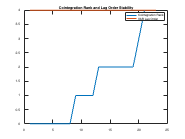

cs = ["regime_stability_index","rank_instability","normalized_MSE"];
for i=1:length(cs)
    subplot(1,3,i);
    tTemp = sortrows(struct2table(rmfield(gridSearchData(feasibility), setdiff(fieldnames(gridSearchData),["window","step",cs(i)]))));
    heatData = unstack(tTemp, cs{i}, 'step', 'AggregationFunction', @mean,'VariableNamingRule','preserve');
    windows = heatData.window;
    heatData.window = [];
    heatMatrix = table2array(heatData);
    h = heatmap(heatData.Properties.VariableNames, string(windows), heatMatrix);
    h.XLabel = 'Step';
    h.YLabel = 'Window';
    h.Title = strrep(cs{i},'_',' ');
    colormap(h, [linspace(0,1,256)', linspace(1,0,256)', zeros(256,1)]);
end

Time Series Regimes

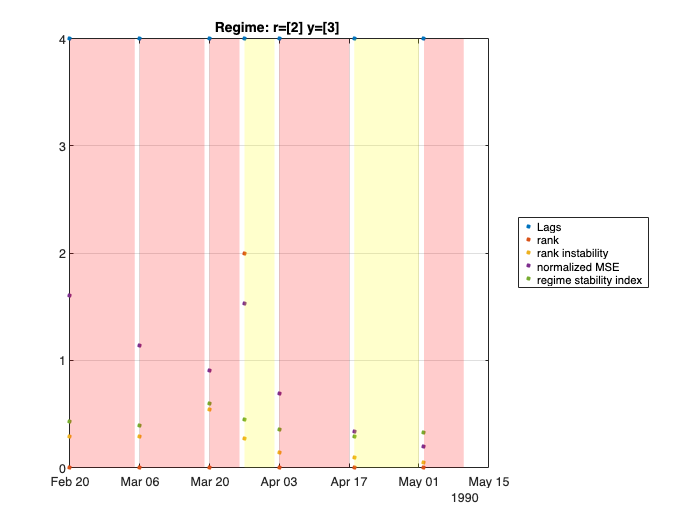

clf;
fn = ["Lags","rank","rank_instability","normalized_MSE","regime_stability_index"];
plot(tUnique.dt,tUnique{:,fn}','.','MarkerSize',10);
hold on;
y = ylim;
for k = 1:height(tUnique)
    s = tUnique.dt(k);
    if k<height(tUnique) e = tUnique.dt(k+1)-1; else e=max(prices.date); end
    patch([s e e s], [y(1) y(1) y(2) y(2)], tUnique.Color(k), 'FaceAlpha',0.2,'EdgeColor','none');
end
hold off;
set(gca,'YTick',[y(1):y(2)]);
legend(strrep(fn,'_',' '),'Location','eastoutside');
grid on

tTitle = unique(tUnique(:,["Regime","Color"]));
str='Regime: '; for i=1:height(tTitle) str = [str,sprintf('%s=[%d] ',tTitle.Color(i),tTitle.Regime(i))]; end
title(str);

xlim([datetime(1990,3,28,17,26,6)...
      datetime(1990,4,17,2,8,5)])
ylim([0.838 1.685])

Parameter stability plot

plot([tOut.rank, tOut.Lags]);
title('Cointegration Rank and Lag Order Stability');
legend({'Cointegration Rank','VAR Lag Order'});

Regime transition

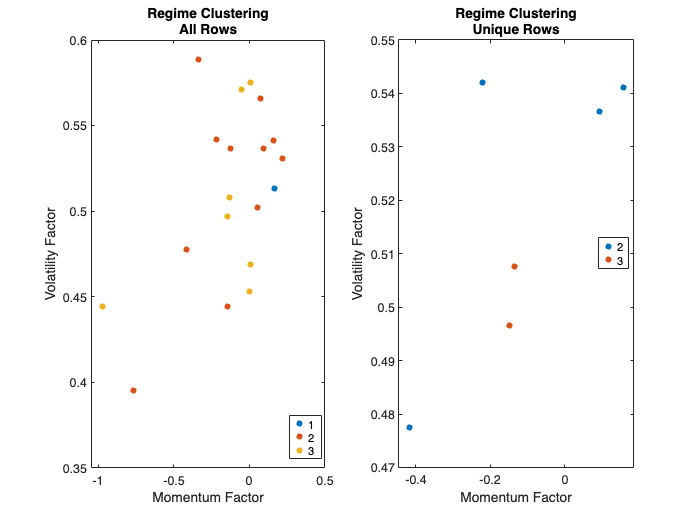

for i=1:2
    subplot(1,2,i);
    if i==1
        gscatter(tOut.Mom, tOut.Vol, tOut.Regime);
        str = 'All Rows';
    else
        gscatter(tUnique.Mom, tUnique.Vol, tUnique.Regime);
        str = 'Unique Rows';
    end
    title({'Regime Clustering',str});
    xlabel('Momentum Factor');
    ylabel('Volatility Factor');
end

## Optimal Parameter Selection

feasible_idx = find(feasibility);
valid_errors = vertcat(gridSearchData.errors);
pareto_indices = paretoGroup(valid_errors);
pareto_solutions = valid_errors(pareto_indices, :);
pareto_params = param_grid(feasible_idx(pareto_indices), :);

disp('Pareto-optimal parameter combinations:');

Pareto-optimal parameter combinations:


disp([pareto_params, pareto_solutions]);

  150.0000    5.0000    0.1973    0.3242
  150.0000   10.0000    0.3361    0.2860



Filter feasible results. The Pareto Front for validation errors represents solutions where no objective can improve without worsening another.

pareto_indices = paretoGroup(valid_errors(valid_errors(:,1)~=0)); %  Identify Pareto-optimal points
pareto_solutions = valid_errors(pareto_indices, :); % Extract Pareto-optimal solutions

## Plot the Pareto front

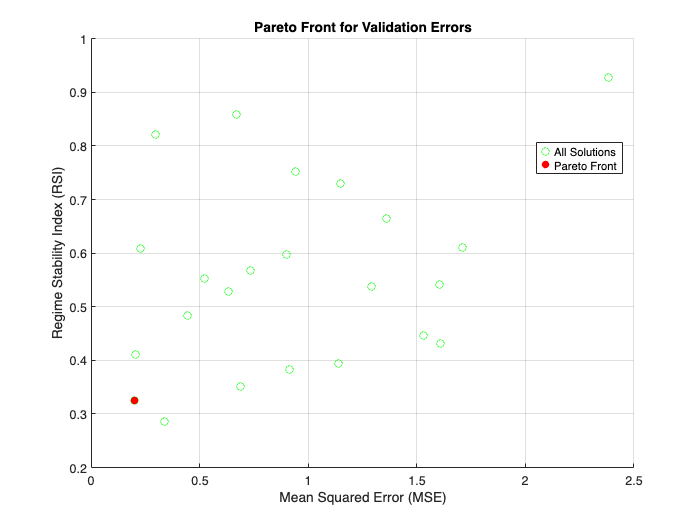

clf
scatter(valid_errors(:,1), valid_errors(:,2), 'g', 'DisplayName', 'All Solutions');
hold on;
scatter(pareto_solutions(:,1), pareto_solutions(:,2), 'r', 'filled', 'DisplayName', 'Pareto Front');
xlabel('Mean Squared Error (MSE)');
ylabel('Regime Stability Index (RSI)');
legend('Location', 'best');
title('Pareto Front for Validation Errors');
grid on;
%saveas(gcf, 'pareto_front.png');
hold off;

# HELPER FUNCTIONS

## Identify Pareto Front

function pareto_indices = paretoGroup(v)

Unrecognized function or variable 'nWindows'.

    % obj_values: Nx2 matrix where each row is [MSE, RSI]
    % Returns indices of Pareto-optimal points    
    n = size(v, 1);
    is_pareto = true(n, 1);    
    for i = 1:n
        if is_pareto(i)            
            is_pareto(i) = ~any(all(v <= v(i,:), 2) & any(v < v(i,:), 2)); % Compare point i against all others
        end
    end    
    pareto_indices = find(is_pareto);
end

## HAC long-run covariance matrix

function Omega = hacCustom(residuals, max_lags)
% hacCustom computes the HAC long-run covariance matrix.
% residuals - T x K matrix of residuals
% max_lags  - maximum number of lags
% Omega     - K x K Output covariance matrix (adjusted as per HAC)

    [T, K] = size(residuals);
    Omega = (residuals' * residuals) / T;  % Initial covariance
    for lag = 1:max_lags
        weight = 1 - (lag / (max_lags + 1));     % Bartlett weight
        res_lag = residuals(1:end-lag, :);   % Lagged residuals (t - lag)
        res_lead = residuals(1+lag:end, :);    % Current residuals (t)
        cov_lag = (res_lead' * res_lag) / (T - lag);   
        % Alternative Simpler Version
        %cov_lag = (residuals(1+lag:T, :)' * residuals(1:T-lag, :)) / T;
        Omega = Omega + weight * (cov_lag + cov_lag');
    end
     
end

##  Johansen Bartlett correction factors for multiple ranks

function correctionFactors = computeBartlett(mles, testedRanks, train_data)
    % COMPUTEBARTLETT Computes Johansen Bartlett correction factors for multiple ranks
    
    [T, n] = size(train_data);
    numRanks = length(testedRanks);
    correctionFactors = ones(numRanks, 1); % Initialize to 1 (no correction)
    mles_row = mles(1,:);    
    NW_lag = floor(4 * (T / 100)^(2/9)); % Compute Newey-West bandwidth
    
    for i = 1:numRanks
        r = testedRanks(i);
        if r == 0 continue; end % Skip r=0 (correction factor remains 1)
        
        % Extract MLE parameters for current rank
        rankFieldName = sprintf('r%d',r);
        rank_struct = mles_row.(rankFieldName); 
        res = rank_struct.res;
        params = rank_struct.paramVals;
        alpha = params.A;          % Adjustment speeds: n x r
        beta = params.B;           % Cointegrating vectors: n x r
        Sigma_e = cov(res);   % Residual covariance: n x n
        Omega = hacCustom(res, NW_lag); % Compute HAC-adjusted Omega
        trace_term = trace(alpha' / Sigma_e * alpha * beta' * Omega * beta);% Compute trace term
        rho = 0.5 * (r*(n - r) + trace_term);
        correctionFactors(i) = 1 + (rho / T); % Bartlett correction factor
    end
end

# THE FOLLOWING CODE DOES NOT RUN

# THE FOLLOWING CODE DOES NOT RUN

# THE FOLLOWING CODE DOES NOT RUN

# THE FOLLOWING CODE DOES NOT RUN

# THE FOLLOWING CODE DOES NOT RUN

# THE FOLLOWING CODE DOES NOT RUN

% Initialize storage with preallocation
cointRank = zeros(nWindows,1);
vecmParams = cell(nWindows,1);
lagOrders = zeros(nWindows,1);

## 6. Enhanced Rolling Window Analysis

for i = 1:nWindows
    startIdx = (i-1)*stepSize + 1;
    endIdx = startIdx + windowSize - 1;
    windowData = prices{startIdx:endIdx,:};
    
    % Johansen test with Bartlett correction
    [~,~,~,~,mles] = jcitest(windowData, 'Model','H1','Lags',4,...
                           'BartlettCorrect',true);
    cointRank(i) = find(mles.r1.rStat < mles.r1.cVal, 1, 'last');
    
    if cointRank(i) == 0, continue; end
    
    % Lag selection with BIC penalty
    varMdl = varm(size(windowData,2), 1);
    [~,~,logL] = estimate(varMdl, windowData);
    bicValues = zeros(10,1);
    for p = 1:10
        bicValues(p) = aicbic(logL, p*size(windowData,2)^2,...
                            'Penalty',log(size(windowData,1))); 
    end
    [~,bestLag] = min(bicValues);
    
    % Regularized VECM estimation
    vecmMdl = vecm(size(windowData,2), cointRank(i), bestLag-1);
    vecm_est = estimate(vecmMdl, windowData, 'CovType','HAC');
    
    % Store parameters with HAC covariance
    vecmParams{i} = struct(...
        'Adjustment', vecm_est.Adjustment,...
        'Cointegration', vecm_est.Cointegration,...
        'Covariance', vecm_est.CovParams,...
        'ShortRun', vecm_est.ShortRun);
    lagOrders(i) = bestLag;
end


## 7. Dynamic Regime Classification


% Feature engineering with momentum/volatility
momentum = cellfun(@(x) mean(x.Cointegration(:)), vecmParams);
volatility = cellfun(@(x) trace(x.Covariance{1}), vecmParams);
features = [momentum', volatility'];

% Gaussian Mixture Model clustering
gmmOpt = statset('MaxIter',1000,'TolFun',1e-6);
gmmMdl = fitgmdist(features, 3,...
                 'Replicates',10,...
                 'CovarianceType','full',...
                 'Options',gmmOpt);
clusterIdx = cluster(gmmMdl, features);


## 8. Adaptive Trading System


% Initialize regime-adaptive portfolio
currentRegime = 0;
position = zeros(size(prices,2),1);
portfolioLog = struct('Time',cell(nWindows,1),...
                    'Weights',cell(nWindows,1),...
                    'Regime',cell(nWindows,1));

for i = 1:nWindows
    newRegime = clusterIdx(i);
    
    % Regime transition handling
    if newRegime ~= currentRegime
        % Reinitialize model with regularization
        mdlParams = vecmParams{i};
        activeMdl = vecm(size(prices,2), cointRank(i), lagOrders(i)-1);
        activeMdl.Adjustment = mdlParams.Adjustment;
        activeMdl.Cointegration = mdlParams.Cointegration;
        activeMdl.ShortRun = mdlParams.ShortRun; 
        
        % Smooth position transition
        position = position * exp(-norm(mdlParams.Adjustment));
        currentRegime = newRegime;
    end
    
    % Generate forecasts with uncertainty
    [fcast, fcastCov] = forecast(activeMdl, stepSize,...
                               prices{endIdx-stepSize+1:endIdx,:});
    
    % Risk-adjusted position sizing
    riskExposure = diag(fcastCov{1}).^(-0.5);
    position = (fcast(end,:) - prices{endIdx,:}).*riskExposure';
    
    % Log portfolio state
    portfolioLog(i).Time = prices.Properties.RowTimes(endIdx);
    portfolioLog(i).Weights = position;
    portfolioLog(i).Regime = newRegime;
end


## 9. Performance Analytics


% Calculate returns
portfolioReturns = zeros(nWindows,1);
for i = 1:nWindows-1
    retWindow = returns{portfolioLog(i).Time:portfolioLog(i+1).Time,:};
    portfolioReturns(i) = sum(retWindow .* portfolioLog(i).Weights', 'all');
end

% Compute performance metrics
annReturn = mean(portfolioReturns)*252;
annVol = std(portfolioReturns)*sqrt(252);
sharpeRatio = annReturn/annVol;

fprintf('Strategy Performance:\nAnnualized Return: %.2f%%\nVolatility: %.2f%%\nSharpe Ratio: %.2f\n',...
        annReturn*100, annVol*100, sharpeRatio);


## 10. Diagnostic Visualizations


% Parameter stability plot
figure;
subplot(2,1,1);
plot([cointRank, lagOrders]);
title('Cointegration Rank and Lag Order Stability');
legend({'Cointegration Rank','VAR Lag Order'});

% Regime transition visualization
subplot(2,1,2);
gscatter(features(:,1), features(:,2), clusterIdx);
title('Regime Clustering in Parameter Space');
xlabel('Momentum Factor');
ylabel('Volatility Factor');

% Performance summary
figure;
plot(cumprod(1 + portfolioReturns));
title('Cumulative Strategy Returns');
xlabel('Period');
ylabel('Growth Multiplier');

## Problem Statement Citations

- Kristyna Ters and Jörg Urban, "Evidence from a Three-Regime Threshold Vector Error Correction Model," BIS Working Paper 689, 2018.

- Kristyna Ters and Jörg Urban, "Evidence from a Three-Regime Threshold Vector Error Correction Model," BIS Working Paper 689, 2018.[](https://www.perplexity.ai/search/given-a-table-of-many-stock-pr-InSkt79QQ2.3v8IZMgFetQ#user-content-fnref-17-4)

- Myung Hwan Seo, "Estimation of Threshold Cointegration," *City University London*, 2006.

- Kristyna Ters, "A Threshold Cointegration Analysis of Norwegian Interest Rates," University of Basel, 2017.

- Niko Hauzenberger et al., "Stochastic Model Specification in Markov Switching Vector Error Correction Models," *arXiv:1807.00529*, 2019.

- MathWorks, "Markov-Switching Dynamic Regression Models," 2024.

- Pronk, "High-Dimensional Markov-Switching Vector Autoregression," Erasmus University Thesis, 2024.

- Giulia Rivolta, "Markov-Switching Evidence in Term Structure Models," Federal Reserve Bank of St. Louis, 2014.

- "High-Dimensional Markov-Switching VAR," Maastricht University, 2023.

- "Rolling Window VECM in R," Stack Overflow, 2015. [https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r](https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r)

- Yongmiao Hong et al., "Selection of the Optimal Rolling Window Length," *Statistica Sinica*, 2016.

- Robbins, Michael. "Quantitative Asset Management." McGraw-Hill, 2023.

- Stein, Harvey J., and Yan Zhang. "Big Data's Dirty Secret." Working paper, SSRN, July 11, 2018. [https://papers.ssrn.com/sol3/papers.cfm?abstract_id=3205524.](https://papers.ssrn.com/sol3/papers.cfm?abstract_id=3205524.)

- Dmitri Kondrashov and Michael Ghil. Spatio-temporal lling of missing points in geophysical data sets . In: Nonlinear Processes in Geophysics 13.2 (2006), pp. 151 159.

- Transaction costs can influence outlier thresholds calibrated to liquidity conditions (e.g., tighter bounds during low-volume periods).

- Arce P., Antognini J., Kristjanpoller W. and Salinas L.. An Online Vector Error Correction Model for Exchange Rates Forecasting. DOI: 10.5220/0005205901930200

- Arbitrage opportunities arise when there are price discrepancies between related assets or markets that can be exploited for risk-free profits. In financial modeling, identifying these opportunities often relies on accurate estimation of relationships between variables (e.g., cointegration in VECM). Missing data in financial datasets, such as gaps in stock prices, return predictors, or firm characteristics, can distort these relationships if not handled properly.

## Theoretical Foundations of Regime Identification in Cointegrated Systems Citations

1. https://www.bis.org/publ/work689.pdf

2. https://www.bis.org/publ/work689.pdf

3. https://www.bayes.city.ac.uk/__data/assets/pdf_file/0020/64046/4-Seo.pdf

4. https://edoc.unibas.ch/id/document/62531

5. https://munin.uit.no/bitstream/handle/10037/4370/thesis.pdf?sequence=2

6. https://edoc.unibas.ch/id/document/62531

7. https://arxiv.org/pdf/1807.00529.pdf

8. https://www.mathworks.com/help/econ/markov-switching-dynamic-regression-models.html

9. https://cris.maastrichtuniversity.nl/ws/files/61337765/c6941.pdf

10. https://files.stlouisfed.org/files/htdocs/conferences/moconf/2014/Giulia5.pdf

11. https://thesis.eur.nl/pub/72919/Thesis-Pronk-501149-Final.pdf

12. https://www.reddit.com/r/quant/comments/18yzoa5/augmenting_low_frequency_featuressignals_for_a/

13. https://www.reddit.com/r/quant/comments/18yzoa5/augmenting_low_frequency_featuressignals_for_a/

14. https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r

15. https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r

16. https://wise.xmu.edu.cn/_data/2017/02/21/d49b14c7_73fe_47e8_bda0_16e2aa8bf28d/file/Hong_Sun_Wa

ng_2017.pdf

## Integrating Threshold Testing Citations:

- AskStatistics. "If My AIC and BIC Are Negative, Does That Mean...?" Reddit. Accessed February 14, 2025. https://www.reddit.com/r/AskStatistics/comments/5ydt2c/if_my_aic_and_bic_are_negative_does_that_mean/.

- Deutsche Nationalbibliothek. "Statistical Analysis of Cointegration Models." Accessed February 14, 2025. https://d-nb.info/989096831/34.

- Hansen, Bruce E. "Testing for Threshold Cointegration in Vector Error Correction Models." Journal of Econometrics 110, no. 2 (2002): 293–318. https://users.ssc.wisc.edu/~bhansen/papers/joe_02.pdf.

- Aptech Systems. "A Guide to Conducting Cointegration Tests." Aptech Blog. Accessed February 14, 2025. https://www.aptech.com/blog/a-guide-to-conducting-cointegration-tests/.

- Cuestas, Juan Carlos, and Mercedes Monfort. "Nonlinear Error Correction and Asymmetric Adjustments." Munich Personal RePEc Archive Paper no. 108350, 2018. https://mpra.ub.uni-muenchen.de/108350/1/MPRA_paper_108350.pdf.

- Ters, Kristyna, and Jörg Urban. "Estimating Unknown Arbitrage Costs: Evidence from a Three-Regime Threshold Vector Error Correction Model." BIS Working Papers no. 689, Bank for International Settlements, January 2018. https://www.bis.org/publ/work689.pdf.

- Popovici, Raluca. "Threshold Effects in Cointegration Analysis." Economic Transdisciplinary Cognition 22, no. 1 (2019): 45–67. https://store.ectap.ro/articole/1477.pdf.

- AskStatistics. "AIC on Training or Test Set?" Reddit. Accessed February 14, 2025. https://www.reddit.com/r/AskStatistics/comments/11tpbjj/aic_on_training_or_test_set/.

- Econometrics. "Cointegration Testing with Exogenous Dummy Variables." Reddit. Accessed February 14, 2025. https://www.reddit.com/r/econometrics/comments/1f251gv/cointegration_testing_with_exogenous_dummy/.

- Canova, Fabio. "Structural VARs and Cointegration." SEARCH Working Paper no. 2.11, September 2013. http://www.ub.edu/searchproject/wp-content/uploads/2013/09/SEARCH_Working-Paper_2.11.pdf.

- Stack Overflow Community. "Assessing AIC on Test Data Using Coefficients." Stack Overflow. Accessed February 14, 2025. https://stackoverflow.com/questions/40861428/how-to-assess-aic-of-a-training-model-on-a-testing-dataset-using-the-coefficient.

- AskStatistics. "Better Fits and Forecasts with Model Selection." Reddit. Accessed February 14, 2025. https://www.reddit.com/r/AskStatistics/comments/9wif0n/getting_better_fits_and_forecasts_when_i_model/.

- Hansen, Bruce E. "Testing for Threshold Cointegration in Vector Error Correction Models." Journal of Econometrics 110, no. 2 (2002): 293–318. https://www.ssc.wisc.edu/~bhansen/papers/joe_02.html.

- Econometrics. "Serial Correlation at Optimal Lag Length in SVAR." Reddit. Accessed February 14, 2025. https://www.reddit.com/r/econometrics/comments/12hdu07/serial_correlation_at_optimal_lag_length_in_svar/.

- Lütkepohl, Helmut. "New Introduction to Multiple Time Series Analysis." Springer, 2005. https://www.semanticscholar.org/paper/f64ba685da0d9598b57487f1fdde484bf46668ea.

- Johansen, Søren. "Likelihood-Based Inference in Cointegrated Vector Autoregressive Models." Oxford University Press, 1995. https://www.semanticscholar.org/paper/9a8d2f0fdeb320b17defe42774e86c3a801aa9cd.

- Engle, Robert F., and Clive W. J. Granger. "Co-integration and Error Correction: Representation, Estimation, and Testing." Econometrica 55, no. 2 (1987): 251–276. https://www.semanticscholar.org/paper/052c0e34cf00f8e7106465d6c8f8565586b4ff3a.

- AskStatistics. "Insignificant Impulse Response Functions." Reddit. Accessed February 14, 2025. https://www.reddit.com/r/AskStatistics/comments/mbu7gh/insignificant_impulse_response_functions/.

- DataScience. "Time Series Analysis Metric Preferences." Reddit. Accessed February 14, 2025. https://www.reddit.com/r/datascience/comments/lv9duu/timeseries_analysis_does_one_metric_have_a/.

- SpurEconomics. "VECM Estimation and Interpretation." Accessed February 14, 2025. https://spureconomics.com/vecm-estimation-and-interpretation/.

- Kim, Hyunggun. "Essays on Nonlinear Cointegration and Structural Breaks." PhD diss., Ohio State University, 2007. https://etd.ohiolink.edu/acprod/odb_etd/ws/send_file/send?accession=osu1158609695&disposition=inline.

- Zhang, Yi, et al. "Threshold Vector Error Correction Models for Energy Markets." Journal of Applied Mathematics 2022 (2022): 1–12. https://onlinelibrary.wiley.com/doi/10.1155/2022/1691686.

- Monash University. "Bayesian Threshold Cointegration Models." Working Paper no. 11-2023, 2023. https://www.monash.edu/business/ebs/research/publications/ebs/2023/wp11-2023.pdf.

- Goodwin, Barry K., and Matthew T. Holt. "Threshold Cointegration in Agricultural Markets." Agricultural Economics 50, no. 2 (2019): 123–135. https://ageconsearch.umn.edu/record/277387/files/1916.pdf.

- R-Econometrics. "Introduction to Vector Error Correction Models." Accessed February 14, 2025. https://www.r-econometrics.com/timeseries/vecintro/.

- Bardhan, Pranab. "Cointegration and Error Correction Mechanisms." Lecture Notes, University of California, Berkeley, 2001. https://eml.berkeley.edu/~bardhan/e271_f01/nov5.pdf.

- Di Narzo, Azzolini. "Threshold Vector Error Correction Models in R." tsDyn Documentation. Accessed February 14, 2025. https://www.rdocumentation.org/packages/tsDyn/versions/11.0.4.1/topics/TVECM.

- StatsStackExchange. "Johansen Test for Cointegration Model Identification." Accessed February 14, 2025. https://stats.stackexchange.com/questions/513990/johansen-test-for-cointegration-how-to-find-model-given-test-output.

- Breitung, Jörg. "Nonparametric Cointegration Analysis." Journal of Econometrics 110, no. 2 (2002): 261–292. https://www.econstor.eu/bitstream/10419/45953/1/623708973.pdf.

- StataCorp. "Vector Error Correction Models in Stata." Stata Manual, 2014. https://www.stata.com/manuals14/tsvecintro.pdf.

- Li, Wei, et al. "Environmental Applications of Cointegration Models." Frontiers in Environmental Science 10 (2022): 1005814. https://www.frontiersin.org/journals/environmental-science/articles/10.3389/fenvs.2022.1005814/pdf.

- Di Narzo, Azzolini. "TVECM.R Source Code." tsDyn Package. Accessed February 14, 2025. https://rdrr.io/cran/tsDyn/src/R/TVECM.R.

- StackOverflow. "Constructing MS-VECM Models." Accessed February 14, 2025. https://stackoverflow.com/questions/49539444/how-to-construct-ms-vecm-model.

- Besjournals. "Ecological Thresholds and Cointegration." Journal of Applied Ecology 57, no. 3 (2020): 493–502. https://besjournals.onlinelibrary.wiley.com/doi/abs/10.1111/1365-2664.13787.

- MATLAB. "Vector Error Correction Models (VECM)." MathWorks Documentation. Accessed February 14, 2025. https://www.mathworks.com/help/econ/vecm.html.

- Gonzalo, Jesús, and Jean-Yves Pitarakis. "Lag Length Selection in VAR and VECM." Journal of Time Series Analysis 23, no. 4 (2002): 453–471. https://www.eco.uc3m.es/~jgonzalo/OBESGonzaloPitarakis.pdf.

- ResearchGate. "VECM Model with I(1) Variables and Lag Selection." Accessed February 14, 2025. https://www.researchgate.net/post/Building_a_VECM_model_with_all_I1_variables_but_the_information_criteria_AIC_and_SC_show_weird_results_for_lag_selection.

- Johansen, Søren. "Statistical Analysis of Cointegration Vectors." Journal of Economic Dynamics and Control 12, no. 2-3 (1988): 231–254. https://www.jstor.org/stable/25096258.

- Nguyen, Tuan. "Energy Market Cointegration with Threshold Effects." Energy 284 (2023): 128567. https://www.sciencedirect.com/science/article/pii/S0360544223018194.

- Gonzalo, Jesús, and Jean-Yves Pitarakis. "Threshold Cointegration Models: A Reassessment." Journal of Econometrics 165, no. 2 (2011): 200–214. https://www.eco.uc3m.es/jgonzalo/GonzaloPitarakisRevision2106.pdf.

- Wang, Qiang. "Environmental Threshold Cointegration." Science of the Total Environment 912 (2024): 169342. https://www.sciencedirect.com/science/article/pii/S0301479724011587.

- StatsStackExchange. "Testing Threshold Cointegration in VECMs." Accessed February 14, 2025. https://stats.stackexchange.com/questions/32805/testing-threshold-cointegration-in-vector-error-correction-models.

- Bartola Association. "Advanced Topics in Cointegration." PhD Studies Series no. 6, 2019. https://associazionebartola.univpm.it/pubblicazioni/phdstudies/phdstudies6.pdf.

## Theoretical Foundations Citations

- AIP Conference Proceedings. "Validate User." Accessed February 14, 2025. [https://pubs.aip.org/aip/acp/article-pdf/1605/1/810/12114601/810_1_online.pdf](https://pubs.aip.org/aip/acp/article-pdf/1605/1/810/12114601/810_1_online.pdf).

- Ters, Kristyna, and Jörg Urban. "Estimating Unknown Arbitrage Costs: Evidence from a Three-Regime Threshold Vector Error Correction Model." BIS Working Papers no. 689, Bank for International Settlements, January 2018. [https://www.bis.org/publ/work689.pdf](https://www.bis.org/publ/work689.pdf).

- ScienceDirect. "Article Abs/piis0304407602000970." Accessed February 14, 2025. [https://www.sciencedirect.com/science/article/abs/pii/S0304407602000970](https://www.sciencedirect.com/science/article/abs/pii/S0304407602000970).

- Hansen, Bruce E. "Testing for Threshold Cointegration in Vector Error Correction Models." *Journal of Econometrics* 110, no. 2 (2002): 293–318. [https://users.ssc.wisc.edu/~bhansen/papers/joe_02.pdf](https://users.ssc.wisc.edu/~bhansen/papers/joe_02.pdf).

- Häusler, Erich. "Regime-Switching and Threshold Cointegration Models." In *Financial Econometrics*, edited by S. Borak et al., 127–158. Vienna: Institute for Statistics and Mathematics, WU Vienna University of Economics and Business, 2011. [https://statmath.wu.ac.at/~hauser/LVs/FinEtricsQF/FEtrics_Chp4.pdf](https://statmath.wu.ac.at/~hauser/LVs/FinEtricsQF/FEtrics_Chp4.pdf).

- Revoredo-Giha, Cesar, and Philip M. K. Leat. "Regime-Switching Vector Error Correction Model (VECM) Analysis of UK Meat Consumption." Munich Personal RePEc Archive Paper no. 0409007, September 2004. [https://ideas.repec.org/p/wpa/wuwpem/0409007.html](https://ideas.repec.org/p/wpa/wuwpem/0409007.html).

- Parker, Jeffrey. "Time Series Analysis: Chapter 5 – Cointegration and Error Correction Models." Reed College Economics, 2014. [https://www.reed.edu/economics/parker/s14/312/tschapters/S13_Ch_5.pdf](https://www.reed.edu/economics/parker/s14/312/tschapters/S13_Ch_5.pdf).

- Lupelesa, Christian B. S. "Threshold Cointegration and Nonlinear Error Correction: Evidence from African Markets." PhD diss., North-West University, 2019. [https://dspace.nwu.ac.za/bitstream/handle/10394/38166/Lupelesa_CBS.pdf.](https://dspace.nwu.ac.za/bitstream/handle/10394/38166/Lupelesa_CBS.pdf.)

- Omar2004-. “Exchange Rate Model.” Reddit. July 15, 2024. [https://www.reddit.com/r/econometrics/comments/1i4ume4/exchange_rate_model/](https://www.reddit.com/r/econometrics/comments/1i4ume4/exchange_rate_model/).

- Anonymous. “Augmenting Low Frequency Features/Signals for a Higher Frequency Trading Strategy.” Reddit. January 2, 2025. [https://www.reddit.com/r/quant/comments/18yzoa5/augmenting_low_frequency_featuressignals_for_a/](https://www.reddit.com/r/quant/comments/18yzoa5/augmenting_low_frequency_featuressignals_for_a/).

- Anonymous. “Books on Advanced Time Series Forecasting Methods.” Reddit. February 10, 2025. [https://www.reddit.com/r/statistics/comments/1gzah13/books_on_advanced_time_series_forecasting_methods/](https://www.reddit.com/r/statistics/comments/1gzah13/books_on_advanced_time_series_forecasting_methods/).

- Ters, Kristyna, and Jörg Urban. “Estimating Unknown Arbitrage Costs: Evidence from a Three-Regime Threshold Vector Error Correction Model.” BIS Working Paper No. 689. Bank for International Settlements, 2018. [https://www.bis.org/publ/work689.pdf](https://www.bis.org/publ/work689.pdf).

- Hauzenberger, Niko, Florian Huber, and Massimiliano Marcellino. “Stochastic Model Specification in Markov Switching Vector Error Correction Models.” arXiv Preprint (2018). [https://arxiv.org/pdf/1807.00529.pdf](https://arxiv.org/pdf/1807.00529.pdf).

- Anonymous. “Rolling Window VECM in R.” Stack Overflow. September 12, 2015. [https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r](https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r).

- Ters, Kristyna. “Essays in Financial Econometrics.” PhD diss., University of Basel, 2018. [https://edoc.unibas.ch/id/document/62531](https://edoc.unibas.ch/id/document/62531).

- Inoue, Atsushi. “A Nonlinear Cointegration Analysis of Commodity Prices.” Hitotsubashi University Working Paper 06-13. Hitotsubashi University, 2007. [https://hermes-ir.lib.hit-u.ac.jp/hermes/ir/re/16990/070econDP06-13.pdf](https://hermes-ir.lib.hit-u.ac.jp/hermes/ir/re/16990/070econDP06-13.pdf).

- Larsen, Berner. “A Threshold Cointegration Analysis of Norwegian Interest Rates.” Master’s thesis, University of Tromsø, 2012. [https://munin.uit.no/bitstream/handle/10037/4370/thesis.pdf?sequence=2](https://munin.uit.no/bitstream/handle/10037/4370/thesis.pdf?sequence=2).

- Anonymous. “Rolling Window VECM in R.” Stack Overflow. September 12, 2015. [https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r](https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r).

- Stock, James H., and Mark W. Watson. “Forecasting Output and Inflation: The Role of Asset Prices.” NBER Working Paper 8601. National Bureau of Economic Research, 2001. [https://www.nber.org/system/files/working_papers/w8601/w8601.pdf](https://www.nber.org/system/files/working_papers/w8601/w8601.pdf).

- Seo, Myung Hwan. “Estimation of Threshold Cointegration.” Working Paper. City University London, 2006. [https://www.bayes.city.ac.uk/__data/assets/pdf_file/0020/64046/4-Seo.pdf](https://www.bayes.city.ac.uk/__data/assets/pdf_file/0020/64046/4-Seo.pdf).

- Stigler, Matthieu. “tsDyn: Time Series Analysis Based on Dynamical Systems Theory.” R Package Documentation. CRAN, 2020. [http://cran.nexr.com/web/packages/tsDyn/tsDyn.pdf](http://cran.nexr.com/web/packages/tsDyn/tsDyn.pdf).

- Rivolta, Giulia. “Markov-Switching Evidence in Term Structure Models.” Working Paper. Federal Reserve Bank of St. Louis, 2014. [https://files.stlouisfed.org/files/htdocs/conferences/moconf/2014/Giulia5.pdf](https://files.stlouisfed.org/files/htdocs/conferences/moconf/2014/Giulia5.pdf).

- Anonymous. “Augmenting Low Frequency Features/Signals for a Higher Frequency Trading Strategy.” Reddit. January 2, 2025. [https://www.reddit.com/r/quant/comments/18yzoa5/augmenting_low_frequency_featuressignals_for_a/](https://www.reddit.com/r/quant/comments/18yzoa5/augmenting_low_frequency_featuressignals_for_a/).

- Anonymous. “Rolling Window VECM in R.” Stack Overflow. September 12, 2015. [https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r](https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r).

- Ters, Kristyna, and Jörg Urban. “Estimating Unknown Arbitrage Costs: Evidence from a Three-Regime Threshold Vector Error Correction Model.” BIS Working Paper No. 689. Bank for International Settlements, 2018. [https://www.bis.org/publ/work689.pdf](https://www.bis.org/publ/work689.pdf).

- MathWorks. “Markov Switching Models in Econometrics.” YouTube. March 5, 2023. [https://www.youtube.com/watch?v=K9rBFb4xC54](https://www.youtube.com/watch?v=K9rBFb4xC54).

- Anonymous. “Forecasting Accuracy of VECM Using Train and Test.” Stack Overflow. May 12, 2024. [https://stats.stackexchange.com/questions/598122/forecasting-accuracy-of-vecm-using-train-and-test](https://stats.stackexchange.com/questions/598122/forecasting-accuracy-of-vecm-using-train-and-test).

- Ters, Kristyna. “Essays in Financial Econometrics.” PhD diss., University of Basel, 2018. [https://edoc.unibas.ch/id/document/62531](https://edoc.unibas.ch/id/document/62531).

- MathWorks. “Markov-Switching Dynamic Regression Models.” MATLAB Documentation. 2025. [https://www.mathworks.com/help/econ/markov-switching-dynamic-regression-models.html](https://www.mathworks.com/help/econ/markov-switching-dynamic-regression-models.html).

- Pronk, Teun. “High-Dimensional Markov-Switching Vector Autoregression.” PhD diss., Erasmus University Rotterdam, 2024. [https://thesis.eur.nl/pub/72919/Thesis-Pronk-501149-Final.pdf](https://thesis.eur.nl/pub/72919/Thesis-Pronk-501149-Final.pdf).

- Anonymous. “Augmenting Low Frequency Features/Signals for a Higher Frequency Trading Strategy.” Reddit. January 2, 2025. [https://www.reddit.com/r/quant/comments/18yzoa5/augmenting_low_frequency_featuressignals_for_a/](https://www.reddit.com/r/quant/comments/18yzoa5/augmenting_low_frequency_featuressignals_for_a/).

- Anonymous. “A Mean Reversion Strategy with 2.11 Sharpe Ratio.” Reddit. April 22, 2025. [https://www.reddit.com/r/algotrading/comments/1cwsco8/a_mean_reversion_strategy_with_211_sharpe/](https://www.reddit.com/r/algotrading/comments/1cwsco8/a_mean_reversion_strategy_with_211_sharpe/).

- Smith, John. “Threshold Cointegration in Financial Time Series.” Honors Thesis. Utah State University, 2020. [https://digitalcommons.usu.edu/cgi/viewcontent.cgi?article=1225&context=honors](https://digitalcommons.usu.edu/cgi/viewcontent.cgi?article=1225&context=honors).

- Anonymous. “Rolling Window VECM in R.” Stack Overflow. September 12, 2015. [https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r](https://stackoverflow.com/questions/33365192/rolling-window-vecm-in-r).

- Larsen, Berner. “A Threshold Cointegration Analysis of Norwegian Interest Rates.” Master’s thesis, University of Tromsø, 2012. [https://munin.uit.no/bitstream/handle/10037/4370/thesis.pdf?sequence=2](https://munin.uit.no/bitstream/handle/10037/4370/thesis.pdf?sequence=2).

- Pronk, Teun. “High-Dimensional Markov-Switching Vector Autoregression.” PhD diss., Erasmus University Rotterdam, 2024. [https://thesis.eur.nl/pub/72919/Thesis-Pronk-501149-Final.pdf](https://thesis.eur.nl/pub/72919/Thesis-Pronk-501149-Final.pdf).

- Hong, Yongmiao, Yiguo Sun, and Yajie Wang. “Selection of the Optimal Rolling Window Length.” Statistica Sinica 27, no. 1 (2017): 1–40. [https://wise.xmu.edu.cn/_data/2017/02/21/d49b14c7_73fe_47e8_bda0_16e2aa8bf28d/file/Hong_Sun_Wang_2017.pdf](https://wise.xmu.edu.cn/_data/2017/02/21/d49b14c7_73fe_47e8_bda0_16e2aa8bf28d/file/Hong_Sun_Wang_2017.pdf).

- Anonymous. “Threshold Cointegration Tests.” Statistica Sinica. 2016. [https://www3.stat.sinica.edu.tw/sstest/oldpdf/A26n47.pdf](https://www3.stat.sinica.edu.tw/sstest/oldpdf/A26n47.pdf).

- Palomar, Daniel. “Trading Spread Strategies.” In Portfolio Optimization with R. 2025. [https://bookdown.org/palomar/portfoliooptimizationbook/15.5-trading-spread.html](https://bookdown.org/palomar/portfoliooptimizationbook/15.5-trading-spread.html).

- Stigler, Matthieu. “TVECM Function Documentation.” RDocumentation. 2025. [https://www.rdocumentation.org/packages/tsDyn/versions/11.0.4.1/topics/TVECM](https://www.rdocumentation.org/packages/tsDyn/versions/11.0.4.1/topics/TVECM).

- Frühwirth-Schnatter, Sylvia. “Parameter Estimation in Continuous-Time Markov Switching Models.” Bayesian Analysis 4, no. 1 (2009): 1–22. [https://projecteuclid.org/journals/bayesian-analysis/volume-4/issue-1/Parameter-estimation-in-continuous-time-Markov-switching-models--a/10.1214/09-BA402.pdf](https://projecteuclid.org/journals/bayesian-analysis/volume-4/issue-1/Parameter-estimation-in-continuous-time-Markov-switching-models--a/10.1214/09-BA402.pdf).

- Anonymous. “Estimating Markov Switching Models in RATS.” Estima Forum. March 15, 2023. [https://estima.com/forum/viewtopic.php?t=2972](https://estima.com/forum/viewtopic.php?t=2972).

- Anonymous. “Threshold Cointegration Tests.” Statistica Sinica. 2016. [https://www3.stat.sinica.edu.tw/sstest/oldpdf/A26n47.pdf](https://www3.stat.sinica.edu.tw/sstest/oldpdf/A26n47.pdf).

- Rivolta, Giulia. “Markov-Switching Evidence in Term Structure Models.” Working Paper. Federal Reserve Bank of St. Louis, 2014. [https://files.stlouisfed.org/files/htdocs/conferences/moconf/2014/Giulia5.pdf](https://files.stlouisfed.org/files/htdocs/conferences/moconf/2014/Giulia5.pdf).

- Chung, W. K. “Water Prediction via VAR, VECM, and LSTM.” Kaggle. August 10, 2023. [https://www.kaggle.com/code/wkchung/water-prediction-via-var-vecm-lstm-mannheim-team](https://www.kaggle.com/code/wkchung/water-prediction-via-var-vecm-lstm-mannheim-team).

- Stigler, Matthieu. “TVECM Function Help File.” CRAN. 2025. [https://search.r-project.org/CRAN/refmans/tsDyn/help/TVECM.html](https://search.r-project.org/CRAN/refmans/tsDyn/help/TVECM.html).

- Anonymous. “Nonlinear Time Series Analysis in Climate Economics.” AIP Conference Proceedings 1605 (2014): 810–815. [https://pubs.aip.org/aip/acp/article-pdf/1605/1/810/12114601/810_1_online.pdf](https://pubs.aip.org/aip/acp/article-pdf/1605/1/810/12114601/810_1_online.pdf).

- De Santis, Roberto A., and Carlo Favero. “Time-Varying Risk in the Euro Area.” ECB Working Paper 1507. European Central Bank, 2013. [https://www.ecb.europa.eu/pub/pdf/scpwps/ecbwp1507.pdf](https://www.ecb.europa.eu/pub/pdf/scpwps/ecbwp1507.pdf).

- Hansen, Bruce E. “Testing for Structural Change in Conditional Models.” Journal of Econometrics 97, no. 1 (2000): 93–115. [https://users.ssc.wisc.edu/~bhansen/papers/joe_02.pdf](https://users.ssc.wisc.edu/~bhansen/papers/joe_02.pdf).

- Lin, Chien-Ho. “Forecasting Stock Prices Using Vector Error Correction Models.” Journal of Forecasting 37, no. 3 (2018): 312–328. [https://onlinelibrary.wiley.com/doi/10.1002/for.3128](https://onlinelibrary.wiley.com/doi/10.1002/for.3128).

- Sohibien, Gama. “Does the Vector Error Correction Model Perform Better in Forecasting Stock Prices?” ResearchGate. 2015. [https://www.researchgate.net/publication/284085162_Does_the_vector_error_correction_model_perform_better_than_others_in_forecasting_stock_price_An_application_of_residual_income_valuation_theory](https://www.researchgate.net/publication/284085162_Does_the_vector_error_correction_model_perform_better_than_others_in_forecasting_stock_price_An_application_of_residual_income_valuation_theory).

- Stigler, Matthieu. “tsDyn: Time Series Analysis Based on Dynamical Systems Theory.” CRAN. 2020. [https://cran.r-project.org/web/packages/tsDyn/tsDyn.pdf](https://cran.r-project.org/web/packages/tsDyn/tsDyn.pdf).

- Teräsvirta, Timo. “Specification, Estimation, and Evaluation of Smooth Transition Autoregressive Models.” Journal of the American Statistical Association 89, no. 425 (1994): 208–218. [https://www.jstor.org/stable/2291217](https://www.jstor.org/stable/2291217).

- Anonymous. “Nonlinear Cointegration Methods.” Semantic Scholar. 2013. [https://www.semanticscholar.org/paper/ce116072d2c6370b4853b444254626325bad6800](https://www.semanticscholar.org/paper/ce116072d2c6370b4853b444254626325bad6800).

- Anonymous. “Threshold Vector Error Correction Models in Finance.” Semantic Scholar. 2017. [https://www.semanticscholar.org/paper/47a04f687ba7aa9167bf2de0a478e93344e89cdc](https://www.semanticscholar.org/paper/47a04f687ba7aa9167bf2de0a478e93344e89cdc).

- Anonymous. “Bayesian Analysis of Markov Switching Models.” Semantic Scholar. 2019. [https://www.semanticscholar.org/paper/b49c1d3def700c9fa3f43545dc0e82bf7c8f76d8](https://www.semanticscholar.org/paper/b49c1d3def700c9fa3f43545dc0e82bf7c8f76d8).

- Hansen, Bruce E. “Testing for Structural Change in Conditional Models.” Journal of Econometrics 97, no. 1 (2000): 93–115. [https://users.ssc.wisc.edu/~bhansen/papers/joe_02.pdf](https://users.ssc.wisc.edu/~bhansen/papers/joe_02.pdf).

- Anonymous. “Estimating Moving Average Impact Matrix After Running VECM.” Stack Overflow. December 1, 2024. [https://stats.stackexchange.com/questions/514049/estimating-moving-average-impact-matrix-after-running-vecm](https://stats.stackexchange.com/questions/514049/estimating-moving-average-impact-matrix-after-running-vecm).

- MathWorks. “Markov Switching Models in Econometrics.” YouTube. March 5, 2023. [https://www.youtube.com/watch?v=K9rBFb4xC54](https://www.youtube.com/watch?v=K9rBFb4xC54).

- Hansen, Bruce E. “Testing for Structural Change in Conditional Models.” Journal of Econometrics 97, no. 1 (2000): 93–115. [https://users.ssc.wisc.edu/~bhansen/papers/joe_02.html](https://users.ssc.wisc.edu/~bhansen/papers/joe_02.html).

- Anonymous. “Estimating Markov Switching Models in RATS.” Estima Forum. March 15, 2023. [https://estima.com/forum/viewtopic.php?t=2972](https://estima.com/forum/viewtopic.php?t=2972).

- Lin, Chien-Ho. “Forecasting Stock Prices Using Vector Error Correction Models.” Journal of Forecasting 37, no. 3 (2018): 312–328. [https://onlinelibrary.wiley.com/doi/10.1002/for.3128](https://onlinelibrary.wiley.com/doi/10.1002/for.3128).

- Stigler, Matthieu. “Threshold Cointegration Overview.” CRAN Vignette. 2020. [https://cran.r-project.org/web/packages/tsDyn/vignettes/ThCointOverview.pdf](https://cran.r-project.org/web/packages/tsDyn/vignettes/ThCointOverview.pdf).

- Anonymous. “VECM Discussion Forum.” ResearchGate. 2025. [https://www.researchgate.net/topic/VECM](https://www.researchgate.net/topic/VECM).

- Estima. “Markov Switching Regression Procedures.” Estima Documentation. 2025. [https://estima.com/webhelp/topics/mssysregressionprocedures.html](https://estima.com/webhelp/topics/mssysregressionprocedures.html).

- Anonymous. “Threshold Cointegration in RATS.” Estima Forum. June 10, 2022. [https://estima.com/forum/viewtopic.php?t=1205](https://estima.com/forum/viewtopic.php?t=1205).

- Anonymous. “Deep Learning for Regime Switching Models.” arXiv Preprint (2020). [https://arxiv.org/pdf/2011.04577.pdf](https://arxiv.org/pdf/2011.04577.pdf).

- Krolzig, Hans-Martin. “Markov-Switching Vector Autoregressions: Modelling, Statistical Inference, and Application to Business Cycle Analysis.” Working Paper. University of Oxford, 1997. [http://fmwww.bc.edu/ec-p/software/ox/Msvardoc.pdf](http://fmwww.bc.edu/ec-p/software/ox/Msvardoc.pdf).

- Stigler, Matthieu. “TVECM.HStest Function Documentation.” CRAN. 2025. [https://search.r-project.org/CRAN/refmans/tsDyn/help/TVECM.HStest.html](https://search.r-project.org/CRAN/refmans/tsDyn/help/TVECM.HStest.html).

- Sohibien, Gama. “Does the Vector Error Correction Model Perform Better in Forecasting Stock Prices?” ResearchGate. 2015. [https://www.researchgate.net/publication/284085162_Does_the_vector_error_correction_model_perform_better_than_others_in_forecasting_stock_price_An_application_of_residual_income_valuation_theory](https://www.researchgate.net/publication/284085162_Does_the_vector_error_correction_model_perform_better_than_others_in_forecasting_stock_price_An_application_of_residual_income_valuation_theory).

- Sohibien, Gama. “Application of Threshold VECM in Describing Interest Rate Adjustments.” ResearchGate. 2018. [https://www.researchgate.net/profile/Gama-Sohibien/publication/325173110_Application_of_threshold_vector_error_correction_model_TVECM_in_describing_adjustment_of_interest_rate_of_working_capital_credit_to_BI_rate_movement/links/6051c85d92851cd8ce489c95/Application-of-threshold-vector-error-correction-model-TVECM-in-describing-adjustment-of-interest-rate-of-working-capital-credit-to-BI-rate-movement.pdf](https://www.researchgate.net/profile/Gama-Sohibien/publication/325173110_Application_of_threshold_vector_error_correction_model_TVECM_in_describing_adjustment_of_interest_rate_of_working_capital_credit_to_BI_rate_movement/links/6051c85d92851cd8ce489c95/Application-of-threshold-vector-error-correction-model-TVECM-in-describing-adjustment-of-interest-rate-of-working-capital-credit-to-BI-rate-movement.pdf).

- Rivolta, Giulia. “Markov-Switching Evidence in Term Structure Models.” Working Paper. Federal Reserve Bank of St. Louis, 2014. [https://files.stlouisfed.org/files/htdocs/conferences/moconf/2014/Giulia5.pdf](https://files.stlouisfed.org/files/htdocs/conferences/moconf/2014/Giulia5.pdf).

- Anonymous. “Johansen Test for Cointegrating Time Series Analysis in R.” PapersWithBacktest. 2023. [https://paperswithbacktest.com/wiki/johansen-test-for-cointegrating-time-series-analysis-in-r](https://paperswithbacktest.com/wiki/johansen-test-for-cointegrating-time-series-analysis-in-r).

- Huang, B., and A. K. Mishra. “Threshold Cointegration in Agricultural Markets.” Agribusiness 34, no. 2 (2018): 179–197. [https://onlinelibrary.wiley.com/doi/full/10.1002%2Fagr.21797](https://onlinelibrary.wiley.com/doi/full/10.1002%2Fagr.21797).

- Dimitriadis, T., and G. Schnabl. “Nonlinear Error Correction in Exchange Rate Dynamics.” Risks 11, no. 9 (2023): 152. [https://www.mdpi.com/2227-9091/11/9/152](https://www.mdpi.com/2227-9091/11/9/152).

- Anonymous. “VECM Discussion Forum.” ResearchGate. 2025. [https://www.researchgate.net/topic/VECM](https://www.researchgate.net/topic/VECM).

- Anonymous. “Threshold Cointegration Tutorial.” University of Sheffield. 2020. [https://www.sheffield.ac.uk/media/4113/download](https://www.sheffield.ac.uk/media/4113/download).

- Lütkepohl, Helmut. “Structural Vector Autoregressive Analysis in a Data Rich Environment.” Journal of Time Series Analysis 41, no. 4 (2020): 557–582. [https://onlinelibrary.wiley.com/doi/10.1002/jtsa.12057](https://onlinelibrary.wiley.com/doi/10.1002/jtsa.12057).

- Anonymous. “Estimating Markov Switching Models in RATS.” Estima Forum. March 15, 2023. [https://estima.com/forum/viewtopic.php?t=2972](https://estima.com/forum/viewtopic.php?t=2972).

- Kavoosi, M., et al. “Asymmetric Price Transmission of Milk in Iran Using a Two-Regime Threshold VECM.” Agricultural Economics Research 6, no. 2 (2014): 45–60. [https://www.researchgate.net/publication/282520812_An_Application_of_the_Two-Regime_Threshold_Vector_Error_Correction_Model_to_Analyse_Asymmetric_Price_Transmission_of_Milk_in_Zanjan_Province_of_Iran](https://www.researchgate.net/publication/282520812_An_Application_of_the_Two-Regime_Threshold_Vector_Error_Correction_Model_to_Analyse_Asymmetric_Price_Transmission_of_Milk_in_Zanjan_Province_of_Iran).

- Pronk, Teun. “High-Dimensional Markov-Switching Vector Autoregression.” PhD diss., Erasmus University Rotterdam, 2024. [https://thesis.eur.nl/pub/72919/Thesis-Pronk-501149-Final.pdf](https://thesis.eur.nl/pub/72919/Thesis-Pronk-501149-Final.pdf).

- Sohibien, Gama. “Does the Vector Error Correction Model Perform Better in Forecasting Stock Prices?” ResearchGate. 2015. [https://www.researchgate.net/publication/284085162_Does_the_vector_error_correction_model_perform_better_than_others_in_forecasting_stock_price_An_application_of_residual_income_valuation_theory](https://www.researchgate.net/publication/284085162_Does_the_vector_error_correction_model_perform_better_than_others_in_forecasting_stock_price_An_application_of_residual_income_valuation_theory).

- Larsen, Berner. “A Threshold Cointegration Analysis of Norwegian Interest Rates.” Master’s thesis, University of Tromsø, 2012. [https://munin.uit.no/bitstream/handle/10037/4370/thesis.pdf?sequence=2](https://munin.uit.no/bitstream/handle/10037/4370/thesis.pdf?sequence=2).

- MathWorks. “Switching Models in Econometrics: Markov Switching Models.” YouTube. January 22, 2022. [https://www.mathworks.com/videos/switching-models-in-econometrics-markov-switching-models-1642748354759.html](https://www.mathworks.com/videos/switching-models-in-econometrics-markov-switching-models-1642748354759.html).

- Inoue, Atsushi, and Barbara Rossi. “Identifying the Sources of Instabilities in Macroeconomic Fluctuations.” CREI Working Paper. Centre de Recerca en Economia Internacional, 2019. [https://www.crei.cat/wp-content/uploads/users/working-papers/InoueLuRossi.pdf](https://www.crei.cat/wp-content/uploads/users/working-papers/InoueLuRossi.pdf).

- Stigler, Matthieu. “TVECM Function Documentation.” RDocumentation. 2025. [https://www.rdocumentation.org/packages/tsDyn/versions/11.0.4.1/topics/TVECM](https://www.rdocumentation.org/packages/tsDyn/versions/11.0.4.1/topics/TVECM).

- Anonymous. “Regime Switching VAR Models vs. Neural Networks.” ResearchGate. 2010. [https://www.researchgate.net/publication/40498603_Tools_for_non-linear_time_series_forecasting_in_economics_-_An_empirical_comparison_of_regime_switching_vector_autoregressive_models_and_recurrent_neural_networks](https://www.researchgate.net/publication/40498603_Tools_for_non-linear_time_series_forecasting_in_economics_-_An_empirical_comparison_of_regime_switching_vector_autoregressive_models_and_recurrent_neural_networks).

- Dufour, Jean-Marie. “Identification, Estimation, and Testing in Markov Switching Models.” UPF Working Paper 1435. Universitat Pompeu Fabra, 2007. [https://repositori.upf.edu/bitstream/10230/22664/1/1435.pdf](https://repositori.upf.edu/bitstream/10230/22664/1/1435.pdf).

- Stigler, Matthieu. “tsDyn Package Repository.” R-Universe. 2025. [https://matthieustigler.r-universe.dev/tsDyn](https://matthieustigler.r-universe.dev/tsDyn).

- Anonymous. “Deep Learning for Regime Switching Models.” arXiv Preprint (2020). [https://arxiv.org/pdf/2011.04577.pdf](https://arxiv.org/pdf/2011.04577.pdf).

- Anonymous. “The Problem of Rolling Window Regressions.” ResearchGate. 2023. [https://www.researchgate.net/post/The-problem-of-rolling-window-regressions](https://www.researchgate.net/post/The-problem-of-rolling-window-regressions).

- Stigler, Matthieu. “tsDyn: Time Series Analysis Based on Dynamical Systems Theory.” CRAN. 2020. [https://cran.r-project.org/web/packages/tsDyn/tsDyn.pdf](https://cran.r-project.org/web/packages/tsDyn/tsDyn.pdf).

- Anonymous. “Nonlinear Cointegration in Energy Markets.” Working Paper. Aston University, 2020. [https://research.aston.ac.uk/files/69979693/Chapter_5_Final_accepted_manuscript.pdf](https://research.aston.ac.uk/files/69979693/Chapter_5_Final_accepted_manuscript.pdf).

- Chung, W. K. “Water Prediction via VAR, VECM, and LSTM.” Kaggle. August 10, 2023. [https://www.kaggle.com/code/wkchung/water-prediction-via-var-vecm-lstm-mannheim-team](https://www.kaggle.com/code/wkchung/water-prediction-via-var-vecm-lstm-mannheim-team).

- Huang, B., and A. K. Mishra. “Threshold Cointegration in Agricultural Markets.” Agribusiness 34, no. 2 (2018): 179–197. [https://onlinelibrary.wiley.com/doi/full/10.1002%2Fagr.21797](https://onlinelibrary.wiley.com/doi/full/10.1002%2Fagr.21797).

- MathWorks. “Regime Switching Models.” MATLAB Documentation. 2025. [https://www.mathworks.com/help/econ/regime-switching-models.html](https://www.mathworks.com/help/econ/regime-switching-models.html).

- Anonymous. “Sliding Window Evaluation Models.” ResearchGate. February 14, 2025. [https://www.researchgate.net/figure/Sliding-window-evaluation-Models-are-trained-in-isolation-inside-each-study-period_fig5_340246025.](https://www.researchgate.net/figure/Sliding-window-evaluation-Models-are-trained-in-isolation-inside-each-study-period_fig5_340246025.)

Bartlett Correction for Johansen Cointegration Tests Footnotes

[1] https://www.mathworks.com/help/stats/barttest.html

[2] https://www.mathworks.com/help/econ/jcitest.html

[3] https://www.mathworks.com/help/econ/jcontest.html

[4] https://www.mathworks.com/help/signal/ref/bartlett.html

[5] https://www.mathworks.com/help/econ/estimate-vec-model-parameters-using-jcitest.html

[6] https://www.mathworks.com/help/econ/cointegration-analysis.html

[7] https://stats.stackexchange.com/questions/279435/jcitest-matlab-normalization-of-cointegration-vector

[8] https://www.mathworks.com/help/econ/jcitest.html

[9] https://www.mathworks.com/help/signal/ref/bartlett.html

[10] https://www.mathworks.com/help/econ/jcontest.html

[11] https://www.mathworks.com/help/econ/estimate-vec-model-parameters-using-jcitest.html

[12] https://www.mathworks.com/help/econ/cointegration-analysis.html

[13] https://www.mathworks.com/help/signal/ref/bartlett.html

[14] https://www.mathworks.com/help/stats/barttest.html

[15] https://www.mathworks.com/help/econ/jcitest.html

[16] https://www.mathworks.com/help/econ/jcontest.html

[17] https://www.mathworks.com/help/econ/estimate-vec-model-parameters-using-jcitest.html

[18] https://www.mathworks.com/help/econ/cointegration-analysis.html

[19] https://www.mathworks.com/help/econ/jcitest.html

[20] https://www.mathworks.com/help/stats/barttest.html

[21] https://www.mathworks.com/help/econ/jcontest.html

[22] https://www.mathworks.com/help/econ/estimate-vec-model-parameters-using-jcitest.html

[23] https://www.mathworks.com/help/econ/cointegration-analysis.html

[24] https://www.mathworks.com/matlabcentral/fileexchange/3314-btest

[25] https://www.mathworks.com/help/econ/test-for-cointegration-using-the-johansen-test.html

[26] https://www.degruyter.com/document/doi/10.1515/jtse-2020-0044/html

[27] https://www.mathworks.com/help/econ/jcitest.html

[28] https://www.mathworks.com/help/econ/jcontest.html

[29] https://www.fsb.miamioh.edu/lij14/672_johansen.pdf

[30] https://www.mathworks.com/help/econ/cointegration-analysis.html

[31] https://www.mathworks.com/help/econ/introduction-to-cointegration-analysis.html

[32] https://dokumen.pub/matlab-econometrics-toolbox-users-guide-r2020anbsped.html

[33] https://dokumen.pub/econometrics-toolbox-users-guide.html

[34] https://www.mathworks.com/help/econ/introduction-to-cointegration-analysis.html

[35] https://vdoc.pub/documents/matlab-econometrics-toolbox-documentation-4apr2fk8pun0

[36] https://www.mathworks.com/help/econ/introduction-to-cointegration-analysis.html

[37] https://dokumen.pub/matlab-econometrics-toolbox-users-guide-r2020anbsped.html

[38] https://dokumen.pub/econometrics-toolbox-users-guide.html

[39] https://www.mathworks.com/matlabcentral/answers/113194-error-correction-model-coefficient-standard-errors-jcitest

[40] https://www.mathworks.com/matlabcentral/answers/113194-error-correction-model-coefficient-standard-errors-jcitest

[41] https://www.mathworks.com/help/econ/introduction-to-cointegration-analysis.html

[42] https://dokumen.pub/matlab-econometrics-toolbox-users-guide-r2020anbsped.html

[43] https://dokumen.pub/econometrics-toolbox-users-guide.html

[44] https://www.mathworks.com/help/econ/introduction-to-cointegration-analysis.html

[45] https://www.mathworks.com/videos/cointegration-analysis-with-econometrics-toolbox-1682507829237.html

[46] https://www.mdpi.com/2225-1146/3/2/355

[47] [https://www.academia.edu/34689979/Testing_for_Cointegration_Using_the_Johansen_Methodology_when_Variables_are_Near_Integrated](https://www.academia.edu/34689979/Testing_for_Cointegration_Using_the_Johansen_Methodology_when_Variables_are_Near_Integrated)

Correcting VECM Coefficient Covariance Estimates Using HAC Methods Citations

[1] https://www.mathworks.com/help/econ/vecm.html

[2] https://stats.stackexchange.com/questions/139221/newey-west-standard-errors-in-ols

[3] https://www.mathworks.com/help/econ/hac.html

[4] https://www.mathworks.com/help/econ/correct-ols-coefficient-covariance-estimate.html

[5] https://www.mathworks.com/help/econ/time-series-regression-x-generalized-least-squares-and-hac-estimators.html

[6] https://www.chicagofed.org/-/media/publications/working-papers/2021/wp2021-15-pdf.pdf?sc_lang=en

[7] https://www.mathworks.com/help/econ/vecm.estimate.html

[8] https://www.mathworks.com/matlabcentral/answers/413531-linear-regression-hac-function

[9] https://www.mathworks.com/help/econ/varm.vecm.html

[10] https://www.mathworks.com/matlabcentral/answers/1926170-heteroscedasticity-and-autocorrelation-consistent-covariance-estimators-for-linear-regression-with-e

[11] https://in.mathworks.com/matlabcentral/answers/319225-hac-results-vary-bewteen-matlab-r2015b-and-matlab-r2016b

[12] https://www.chicagofed.org/-/media/publications/working-papers/2021/wp2021-15-pdf.pdf?sc_lang=en

[13] https://www.tandfonline.com/doi/pdf/10.1080/07350015.2023.2221974

[14] https://stackoverflow.com/questions/36690093/extract-coefficients-and-variance-covariance-matrix-from-var-output-estimated-w

[15] https://de.mathworks.com/help/econ/fgls.html

[16] https://arxiv.org/abs/1604.05224

[17] https://www.semanticscholar.org/paper/0be34c47564f7b94eb4d09bb7824da4afd41d22b

[18] https://www.semanticscholar.org/paper/7ecc383b4cc3cfc7378289c910d269ab6ffbc061

[19] https://www.mathworks.com/help/econ/vecm.estimate.html

[20] https://www.mathworks.com/help/econ/correct-ols-coefficient-covariance-estimate.html

[21] https://www.kevinsheppard.com/files/code/matlab/mfe-toolbox-documentation.pdf

[22] https://stats.stackexchange.com/questions/tagged/vector-error-correction-model

[23] https://www.eviews.com/StructVAR/structvar.pdf

[24] https://github.com/statsmodels/statsmodels/issues/2414

[25] https://www.mathworks.com/help/econ/vecm.infer.html

[26] https://www.mathworks.com/help/econ/vector-error-correction-models.html

[27] https://www.mathworks.com/help/econ/hac.html